%%
%
% <html>
% <style>
%   .matlabcode, .matlabsymbolicoutput, pre { overflow-x: auto !important; white-space: pre !important; }
% </style>
% </html>
%

# Quanser's Rotary Inverted Pendulum

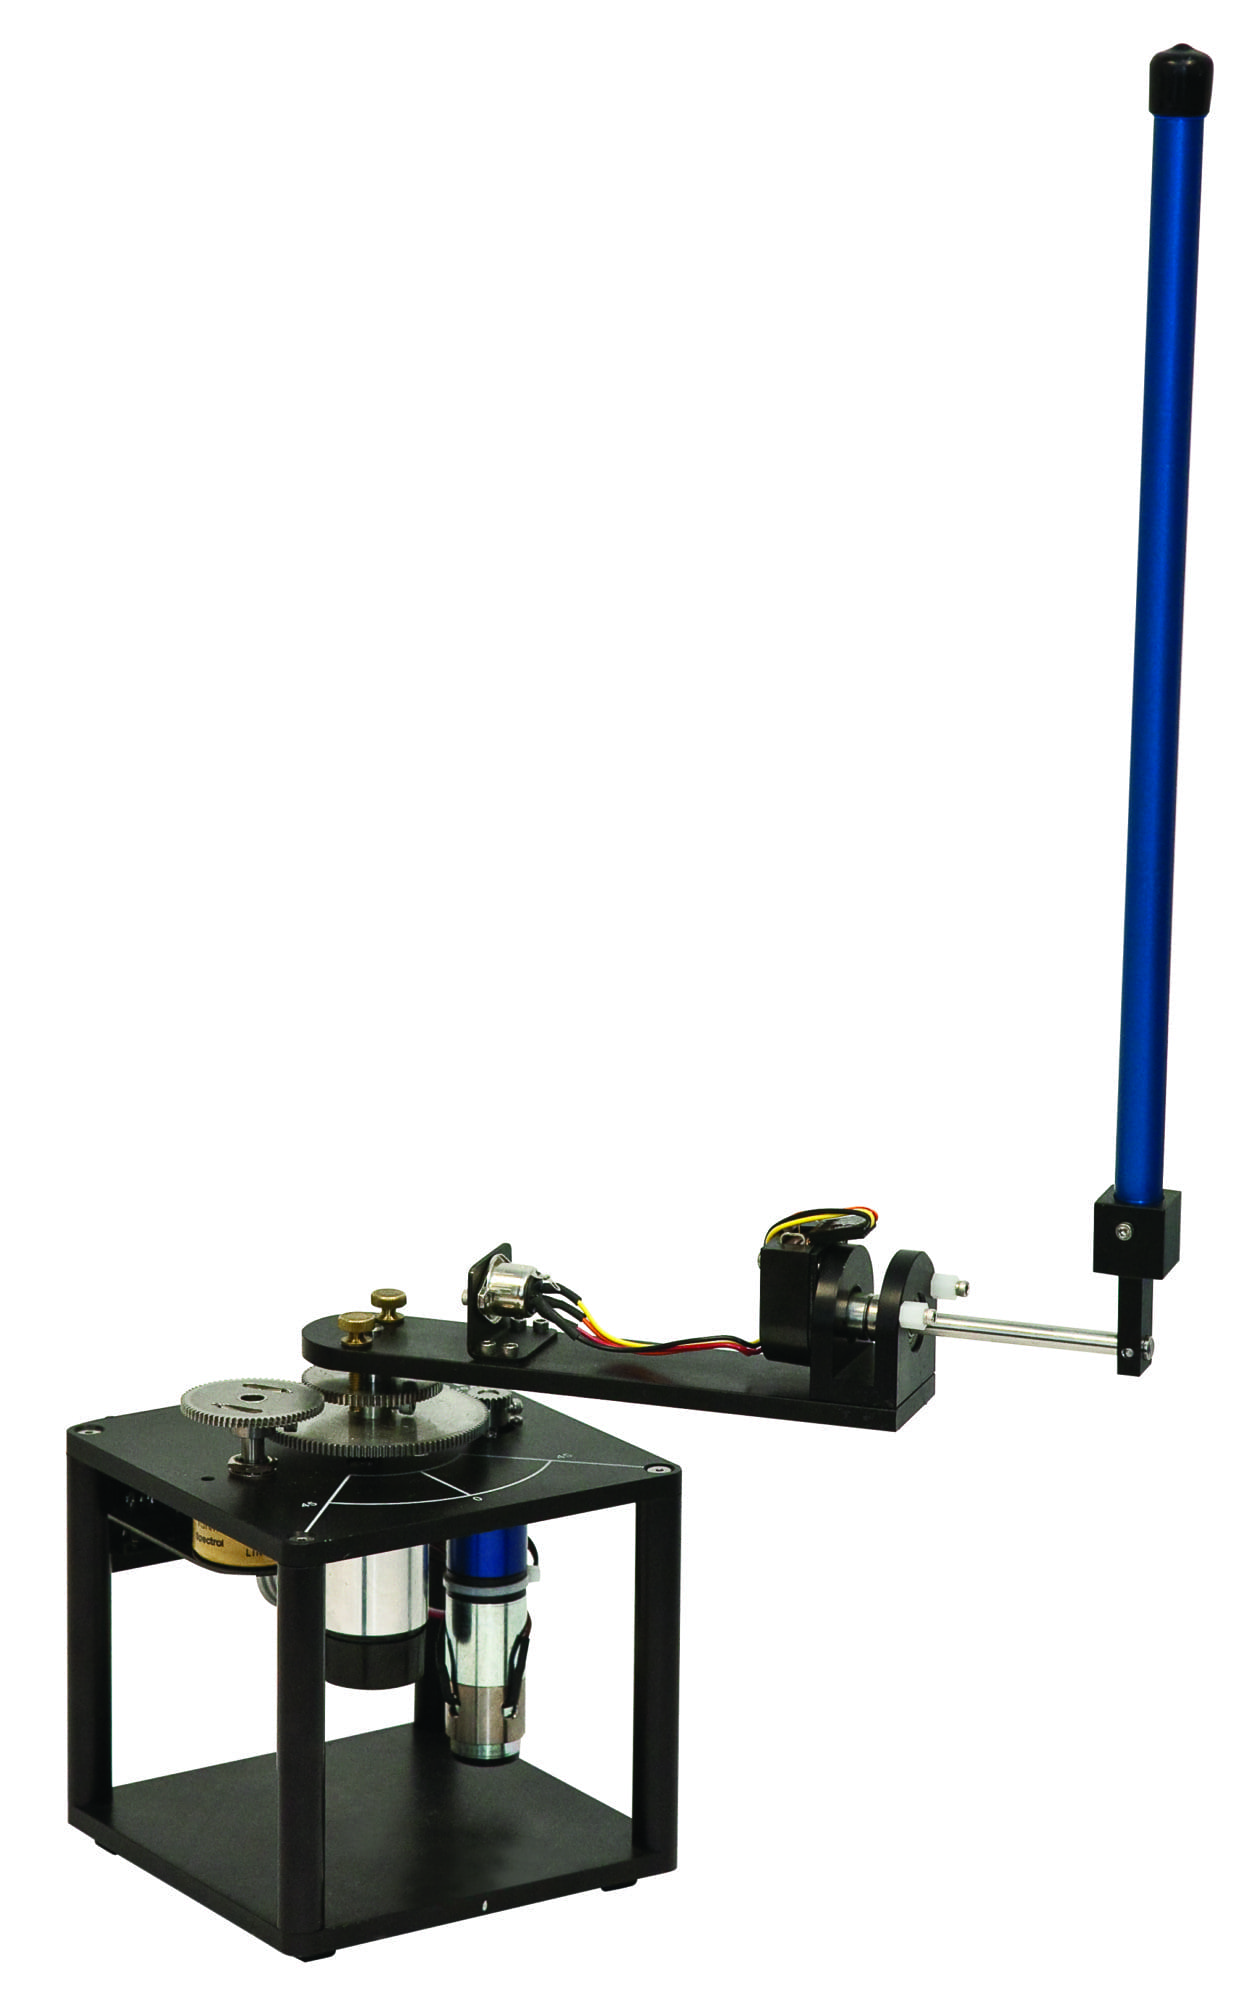                                                 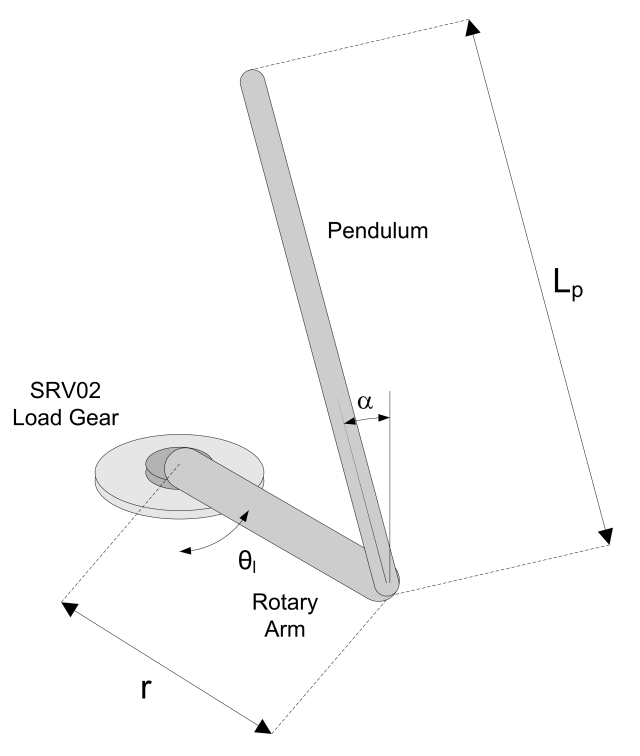

## Introduction

This project serves as a comprehensive study of the rotary inverted pendulum.

% Maintenance
clc; close all; clearvars
sympref('TypesetOutput', true);

## Mathematical Model of Rotary Inverted Pendulum

Note: *Pendulum parameters according to Quanser official documentation and nonlinear equations of motion according to the Quanser Student Workbook.*

### Nonlinear Equations of Motion

syms alpha % Angle of the pendulum arm
syms theta % Angle of the rotary base
syms alpha_dot alpha_ddot theta_dot theta_ddot
syms m_p L_p L_r J_p J_r B_r B_p g 
syms eta_g K_g eta_m k_t V_m k_m R_m

g_val = 9.83;          % Gravitational acceleration (m/s^2)

% Pendulum parameters 
m_p_val = 0.127;          % Pendulum mass (kg)
L_p_val = 0.337;          % Total pendulum length (m)
L_r_val = 0.216;          % Length of the rotary arm from the pivot point to the end (m)alpha
J_p_val = 0.0012;         % Pendulum moment of inertia around the center of mass (kg·m^2)
J_r_val = 0.0020;         % Rotary arm moment of inertia around the center of mass (kg·m^2)
B_p_val = 0.0024;         % Pendulum viscous damping (N·m·s/rad)
B_r_val = 0.0024;         % Arm viscous damping (N·m·s/rad)

% Servo parameters 
R_m_val = 2.6;            % Motor winding resistance (ohms)
k_t_val = 7.68e-3;        % Motor torque constant (N·m/A)
k_m_val = 7.68e-3;        % Motor back-EMF constant (V/(rad/s))
K_g_val = 70;             % Total gear ratio [-]
eta_m_val = 0.69;         % Motor efficiency [-]
eta_g_val = 0.90;         % Gearbox efficiency [-]

% Storing parameters into lists
param_val = [m_p_val, L_p_val, L_r_val, J_p_val, J_r_val, B_p_val, B_r_val, R_m_val, k_t_val, k_m_val, K_g_val, eta_m_val, eta_g_val, g_val];
param_sym = [m_p, L_p, L_r, J_p, J_r, B_p, B_r, R_m, k_t, k_m, K_g, eta_m, eta_g, g];

% Coefficients for equation 1 
C1 = m_p*L_r^2 + (1/4)*m_p*L_p^2 - (1/4)*m_p*L_p^2*cos(alpha)^2 + J_r;
C2 = (1/2)*m_p*L_p*L_r*cos(alpha);
C3 = (1/2)*m_p*L_p^2*sin(alpha)*cos(alpha);
C4 = (1/2)*m_p*L_p*L_r*sin(alpha);

% Coefficients for equation 2 
D1 = (1/2)*m_p*L_p*L_r*cos(alpha);
D2 = J_p + (1/4)*m_p*L_p^2;
D3 = (1/4)*m_p*L_p^2*cos(alpha)*sin(alpha);
D4 = (1/2)*m_p*L_p*g*sin(alpha);

% Input equation (torque tau)
tau = (eta_g * K_g * eta_m * k_t * (V_m - K_g * k_m * theta_dot)) / R_m;

% Set up complete governing differential equations
eq1 = C1*theta_ddot - C2*alpha_ddot + C3*alpha_dot*theta_dot + C4*alpha_dot^2 == tau - B_r*theta_dot;
eq2 = -D1*theta_ddot + D2*alpha_ddot - D3*theta_dot^2 - D4 == -B_p*alpha_dot;

disp(simplify(eq1));

$$\ddot{\theta }\,\left(-\frac{m_{p}\,{L_{p}}^{2}\,{\cos\left(\alpha \right)}^{2}}{4}+\frac{m_{p}\,{L_{p}}^{2}}{4}+m_{p}\,{L_{r}}^{2}+J_{r}\right)-\frac{L_{p}\,L_{r}\,\ddot{\alpha }\,m_{p}\,\cos\left(\alpha \right)}{2}+\frac{L_{p}\,L_{r}\,{\dot{\alpha }}^{2}\,m_{p}\,\sin\left(\alpha \right)}{2}+\frac{{L_{p}}^{2}\,\dot{\alpha }\,m_{p}\,\dot{\theta }\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)}{2}=\frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{t}\,\left(V_{m}-K_{g}\,k_{m}\,\dot{\theta }\right)}{R_{m}}-B_{r}\,\dot{\theta }$$

disp(simplify(eq2));

$$\ddot{\alpha }\,m_{p}\,{L_{p}}^{2}+4\,B_{p}\,\dot{\alpha }+4\,J_{p}\,\ddot{\alpha }=L_{p}\,m_{p}\,\left(L_{p}\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)\,{\dot{\theta }}^{2}+2\,g\,\sin\left(\alpha \right)+2\,L_{r}\,\ddot{\theta }\,\cos\left(\alpha \right)\right)$$

% Solving for alpha_ddot and theta_ddot
[alpha_ddot_sol, theta_ddot_sol] = solve([eq1, eq2], [alpha_ddot, theta_ddot]);

eq_alpha_ddot = alpha_ddot == alpha_ddot_sol;
eq_theta_ddot = theta_ddot == theta_ddot_sol;

Solved for $\ddot{\alpha}$ and $\ddot{\theta}$

disp(eq_alpha_ddot);

$$\ddot{\alpha }=-\frac{8\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,{K_{g}}^{2}\,L_{p}\,L_{r}\,m_{p}\,\dot{\theta }\,\cos\left(\alpha \right)-8\,V_{m}\,\eta_{g}\,\eta_{m}\,k_{t}\,K_{g}\,L_{p}\,L_{r}\,m_{p}\,\cos\left(\alpha \right)+R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{4}\,{m_{p}}^{2}\,{\dot{\theta }}^{2}\,{\cos\left(\alpha \right)}^{3}-R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{4}\,{m_{p}}^{2}\,{\dot{\theta }}^{2}\,\cos\left(\alpha \right)+4\,R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{3}\,L_{r}\,\dot{\alpha }\,{m_{p}}^{2}\,\dot{\theta }\,{\cos\left(\alpha \right)}^{2}+2\,R_{m}\,g\,\sin\left(\alpha \right)\,{L_{p}}^{3}\,{m_{p}}^{2}\,{\cos\left(\alpha \right)}^{2}-2\,R_{m}\,g\,\sin\left(\alpha \right)\,{L_{p}}^{3}\,{m_{p}}^{2}+4\,R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{2}\,{L_{r}}^{2}\,{\dot{\alpha }}^{2}\,{m_{p}}^{2}\,\cos\left(\alpha \right)-4\,R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{2}\,{L_{r}}^{2}\,{m_{p}}^{2}\,{\dot{\theta }}^{2}\,\cos\left(\alpha \right)-4\,B_{p}\,R_{m}\,{L_{p}}^{2}\,\dot{\alpha }\,m_{p}\,{\cos\left(\alpha \right)}^{2}+4\,B_{p}\,R_{m}\,{L_{p}}^{2}\,\dot{\alpha }\,m_{p}-4\,J_{r}\,R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{2}\,m_{p}\,{\dot{\theta }}^{2}\,\cos\left(\alpha \right)-8\,R_{m}\,g\,\sin\left(\alpha \right)\,L_{p}\,{L_{r}}^{2}\,{m_{p}}^{2}+8\,B_{r}\,R_{m}\,L_{p}\,L_{r}\,m_{p}\,\dot{\theta }\,\cos\left(\alpha \right)-8\,J_{r}\,R_{m}\,g\,\sin\left(\alpha \right)\,L_{p}\,m_{p}+16\,B_{p}\,R_{m}\,{L_{r}}^{2}\,\dot{\alpha }\,m_{p}+16\,B_{p}\,J_{r}\,R_{m}\,\dot{\alpha }}{R_{m}\,\left({L_{p}}^{4}\,{m_{p}}^{2}+16\,J_{p}\,J_{r}+4\,{L_{p}}^{2}\,{L_{r}}^{2}\,{m_{p}}^{2}+4\,J_{p}\,{L_{p}}^{2}\,m_{p}+16\,J_{p}\,{L_{r}}^{2}\,m_{p}+4\,J_{r}\,{L_{p}}^{2}\,m_{p}-{L_{p}}^{4}\,{m_{p}}^{2}\,{\cos\left(\alpha \right)}^{2}-4\,{L_{p}}^{2}\,{L_{r}}^{2}\,{m_{p}}^{2}\,{\cos\left(\alpha \right)}^{2}-4\,J_{p}\,{L_{p}}^{2}\,m_{p}\,{\cos\left(\alpha \right)}^{2}\right)}$$

disp(eq_theta_ddot);

$$\ddot{\theta }=-\frac{2\,\left(2\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,{K_{g}}^{2}\,{L_{p}}^{2}\,m_{p}\,\dot{\theta }+8\,J_{p}\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,{K_{g}}^{2}\,\dot{\theta }-2\,V_{m}\,\eta_{g}\,\eta_{m}\,k_{t}\,K_{g}\,{L_{p}}^{2}\,m_{p}-8\,J_{p}\,V_{m}\,\eta_{g}\,\eta_{m}\,k_{t}\,K_{g}+R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{4}\,\dot{\alpha }\,{m_{p}}^{2}\,\dot{\theta }\,\cos\left(\alpha \right)+L_{r}\,R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{3}\,{\dot{\alpha }}^{2}\,{m_{p}}^{2}-L_{r}\,R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{3}\,{m_{p}}^{2}\,{\dot{\theta }}^{2}\,{\cos\left(\alpha \right)}^{2}+4\,J_{p}\,R_{m}\,\sin\left(\alpha \right)\,{L_{p}}^{2}\,\dot{\alpha }\,m_{p}\,\dot{\theta }\,\cos\left(\alpha \right)-2\,L_{r}\,R_{m}\,g\,\sin\left(\alpha \right)\,{L_{p}}^{2}\,{m_{p}}^{2}\,\cos\left(\alpha \right)+2\,B_{r}\,R_{m}\,{L_{p}}^{2}\,m_{p}\,\dot{\theta }+4\,J_{p}\,L_{r}\,R_{m}\,\sin\left(\alpha \right)\,L_{p}\,{\dot{\alpha }}^{2}\,m_{p}+4\,B_{p}\,L_{r}\,R_{m}\,L_{p}\,\dot{\alpha }\,m_{p}\,\cos\left(\alpha \right)+8\,B_{r}\,J_{p}\,R_{m}\,\dot{\theta }\right)}{R_{m}\,\left({L_{p}}^{4}\,{m_{p}}^{2}+16\,J_{p}\,J_{r}+4\,{L_{p}}^{2}\,{L_{r}}^{2}\,{m_{p}}^{2}+4\,J_{p}\,{L_{p}}^{2}\,m_{p}+16\,J_{p}\,{L_{r}}^{2}\,m_{p}+4\,J_{r}\,{L_{p}}^{2}\,m_{p}-{L_{p}}^{4}\,{m_{p}}^{2}\,{\cos\left(\alpha \right)}^{2}-4\,{L_{p}}^{2}\,{L_{r}}^{2}\,{m_{p}}^{2}\,{\cos\left(\alpha \right)}^{2}-4\,J_{p}\,{L_{p}}^{2}\,m_{p}\,{\cos\left(\alpha \right)}^{2}\right)}$$

% Define generalized coordinate vectors
q_ddot = [alpha_ddot; theta_ddot];

% Inertia Matrix M
M = [D2, -D1; 
    -C2,  C1];

% Remaining Forces
F = [ -D3*theta_dot^2 - D4 + B_p*alpha_dot;
       C3*alpha_dot*theta_dot + C4*alpha_dot^2 + B_r*theta_dot + (eta_g*K_g^2*eta_m*k_m*k_t*theta_dot)/R_m ];

% Motor Input
Tau = [0; 
      (eta_g * K_g * eta_m * k_t * V_m) / R_m];

**Inertia Matrix:**

M

$$M = \left(\begin{array}{cc} \frac{m_{p}\,{L_{p}}^{2}}{4}+J_{p} & -\frac{L_{p}\,L_{r}\,m_{p}\,\cos\left(\alpha \right)}{2}\\ -\frac{L_{p}\,L_{r}\,m_{p}\,\cos\left(\alpha \right)}{2} & -\frac{m_{p}\,{L_{p}}^{2}\,{\cos\left(\alpha \right)}^{2}}{4}+\frac{m_{p}\,{L_{p}}^{2}}{4}+m_{p}\,{L_{r}}^{2}+J_{r} \end{array}\right)$$

**Force Vector:**

F

$$F = \left(\begin{array}{c} -\frac{m_{p}\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)\,{L_{p}}^{2}\,{\dot{\theta }}^{2}}{4}-\frac{g\,m_{p}\,\sin\left(\alpha \right)\,L_{p}}{2}+B_{p}\,\dot{\alpha }\\ B_{r}\,\dot{\theta }+\frac{L_{p}\,L_{r}\,{\dot{\alpha }}^{2}\,m_{p}\,\sin\left(\alpha \right)}{2}+\frac{{L_{p}}^{2}\,\dot{\alpha }\,m_{p}\,\dot{\theta }\,\cos\left(\alpha \right)\,\sin\left(\alpha \right)}{2}+\frac{{K_{g}}^{2}\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,\dot{\theta }}{R_{m}} \end{array}\right)$$

**Input Matrix:**

Tau

$$Tau = \left(\begin{array}{c} 0\\ \frac{K_{g}\,V_{m}\,\eta_{g}\,\eta_{m}\,k_{t}}{R_{m}} \end{array}\right)$$

### Nonlinear State Space

% Declare state variables
syms x_1 x_2 x_3 x_4 u

eq_x1 = x_1 == alpha;
eq_x2 = x_2 == alpha_dot;
eq_x3 = x_3 == theta;
eq_x4 = x_4 == theta_dot;

X = [x_1; x_2; x_3; x_4]; % State space
disp([eq_x1; eq_x2; eq_x3; eq_x4]);

$$\left(\begin{array}{c} x_{1}=\alpha \\ x_{2}=\dot{\alpha }\\ x_{3}=\theta \\ x_{4}=\dot{\theta } \end{array}\right)$$

eq_u = u == V_m;
disp(eq_u);

$$u=V_{m}$$

#### State Space Dynamics:

syms x_dot_1 x_dot_2 x_dot_3 x_dot_4

X_dot = [x_dot_1; x_dot_2; x_dot_3; x_dot_4];

eq_x_dot_1 = x_dot_1 == alpha_dot;
eq_x_dot_2 = x_dot_2 == alpha_ddot;
eq_x_dot_3 = x_dot_3 == theta_dot;
eq_x_dot_4 = x_dot_4 == theta_ddot;

X_dot_sol = [rhs(eq_x_dot_1); rhs(eq_x_dot_2); rhs(eq_x_dot_3); rhs(eq_x_dot_4)];

X_dot_sol = subs(X_dot_sol, [alpha_ddot; theta_ddot], [alpha_ddot_sol; theta_ddot_sol]);
X_dot_sol = subs(X_dot_sol, [alpha; alpha_dot; theta; theta_dot; V_m], [X; u]);

disp(X_dot_sol);

#### **Output Equations**

In contrast to the state space, which construction is bound by physical rules, the output equations are chosen by the designer (or by the physical observability of the output) and take shape of any combination of state space variables and inputs. below are examples of typical output equations for this system. Note that the *Qunaser's* rotary inverted pendulum platform provides only the measurements of the pendulum arm angle $\alpha$ and the rotary base position $\theta$. Furthermore, we are also limited by our single input source $u = V_m$ driving the device servo motor.

syms y_1 y_2 Y

**Single Input - Single Output (SISO)**

Observing $\alpha$ ( $SISO_\alpha$ )

SISO_alpha_ss = y_1 == x_1 + 0 * u;
disp(SISO_alpha_ss);

$$y_{1}=x_{1}$$

Observing $\theta$ ( $SISO_\theta$ )

SISO_theta_ss = y_1 == x_3 + 0 * u;
disp(SISO_theta_ss);

$$y_{1}=x_{3}$$

**Single Input - Multiple Outputs (SIMO)**

Observing both $\alpha$ and $\theta$ ( $SIMO$ )

SIMO_mu_CL_uss = [y_1 == x_1 + 0 * u; y_2 == x_3 + 0 * u];
disp(SIMO_mu_CL_uss);

$$\left(\begin{array}{c} y_{1}=x_{1}\\ y_{2}=x_{3} \end{array}\right)$$

Since we are not restricted by observability of the state variables, we can use the SIMO output for further work, as it holds everything together.

#### **Static equilibrium equations (**$\dot{x}_i$*** = 0*****)**

X_dot_sol_s = subs(X_dot_sol, X_dot, [0; 0; 0; 0]);
disp(simplify(collect(X_dot_sol_s)));

Note: *Generally, solving static equilibrium systems leads to infinite solutions, where the input *$u$* becomes a parameter. However, for the rotary inverted pendulum system in the upright position the static equilibrium equations have only one exact solution where *$u = 0$*. The downright position again leads to infinite solutions with *$u$* being a parameter. To simplify solution of static equilibrium equations, we will choose *$u = u_p = 0$* for both positions.*

u_p_val = 0;

% Substituting symbolic parameters with actual values
X_dot_sol_s = subs(X_dot_sol_s, [param_sym, u], [param_val, u_p_val]);

% Solving static equilibrium equations for all states and control
SS_s_sol = solve(X_dot_sol_s, X, 'ReturnConditions', true, 'Real', true);

syms z
SS_s_sol = subs(SS_s_sol, SS_s_sol.parameters(2), z);  % Rename the returned "x" parameter to "z" to avoid confusion with state variables.

X_sol = [SS_s_sol.x_1; SS_s_sol.x_2; SS_s_sol.x_3; SS_s_sol.x_4];

#### Singular Points

disp(X == X_sol);

$$\left(\begin{array}{c} x_{1}=\pi \,k\\ x_{2}=0\\ x_{3}=z\\ x_{4}=0 \end{array}\right)$$

The system technically has infinite singular points given by the two parameters $k\in \mathbb{Z}$ and $z\in \mathbb{R}$. The parameter $k$ represents the cyclical nature of the pendulum and the parameter $z$ represents free angle $\theta$ of the rotary base. Since $\theta$ by itself does not contribute to the system dynamics (only its derivatives $\dot{\theta}$ and $\ddot{\theta}$), we can simply choose our value of $z$ for example $z=0$. With this choice, the system demonstrates only two physically relevant static equilibrium solutions. The **upright** ( $k$ is even number) and the **downright** ( $k$ is odd number) pendulum positions $\rightarrow$ **2** **working points**.

#### **Working points**

% Define the corresponding symbolic variables for comparison
syms x_1_p_up x_1_p_down x_2_p_up x_2_p_down x_3_p_up x_3_p_down x_4_p_up x_4_p_down u_p

X_p_up = [x_1_p_up; x_2_p_up; x_3_p_up; x_4_p_up];
X_p_down = [x_1_p_down; x_2_p_down; x_3_p_down; x_4_p_down];
X_p = [X_p_up, X_p_down];

% upright position (k = 0)
X_p_up_sol = subs(X_sol, SS_s_sol.parameters, [0, 0]);

% downright position (k = 1)
X_p_down_sol = subs(X_sol, SS_s_sol.parameters, [1, 0]);

X_p_sol = [X_p_up_sol, X_p_down_sol];
disp(X_p == X_p_sol);

$$\left(\begin{array}{cc} x_{1,p,\mathrm{up}}=0 & x_{1,p,\mathrm{down}}=\pi \\ x_{2,p,\mathrm{up}}=0 & x_{2,p,\mathrm{down}}=0\\ x_{3,p,\mathrm{up}}=0 & x_{3,p,\mathrm{down}}=0\\ x_{4,p,\mathrm{up}}=0 & x_{4,p,\mathrm{down}}=0 \end{array}\right)$$

### Linear State Space

#### **Simulink model of Linear System**

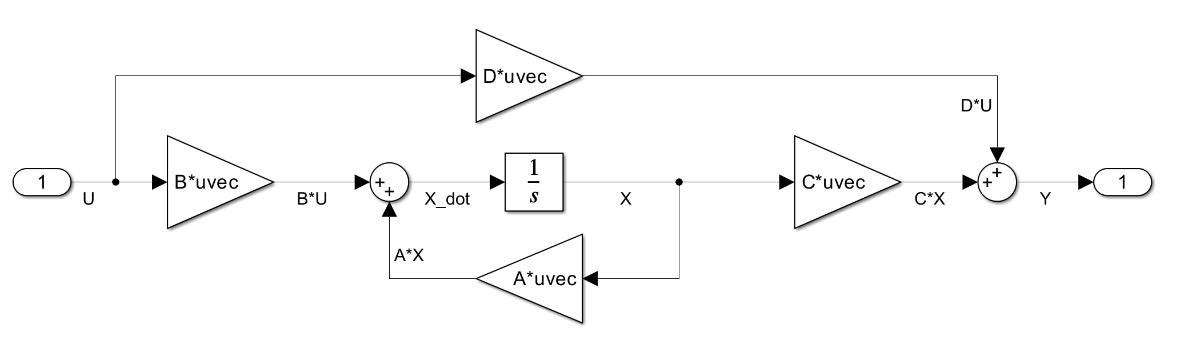

#### Linearization

J_x = jacobian(X_dot_sol, X);
J_u = jacobian(X_dot_sol, u);

J_SIMO_x = [jacobian(rhs(SISO_alpha_ss), X); jacobian(rhs(SISO_theta_ss), X)];
J_SIMO_u = [jacobian(rhs(SISO_alpha_ss), u); jacobian(rhs(SISO_theta_ss), u)];

$J_x$ and $J_u$ represent parametrized matrixes. By substituting our working points into these parametrized equations, we obtain the system dynamic matrix $A$ and the input matrix $B$ respectively for each working point.

#### Linearized Model of The Pendulum in the Upright Position

A_up = subs(J_x,      X, X_p_up_sol)

$$A\_up = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ \frac{8\,L_{p}\,R_{m}\,g\,{L_{r}}^{2}\,{m_{p}}^{2}+8\,J_{r}\,L_{p}\,R_{m}\,g\,m_{p}}{R_{m}\,\sigma_{1}} & -\frac{16\,B_{p}\,R_{m}\,m_{p}\,{L_{r}}^{2}+16\,B_{p}\,J_{r}\,R_{m}}{R_{m}\,\sigma_{1}} & 0 & -\frac{8\,L_{p}\,L_{r}\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,m_{p}\,{K_{g}}^{2}+8\,B_{r}\,L_{p}\,L_{r}\,R_{m}\,m_{p}}{R_{m}\,\sigma_{1}}\\ 0 & 0 & 0 & 1\\ \frac{4\,{L_{p}}^{2}\,L_{r}\,g\,{m_{p}}^{2}}{\sigma_{1}} & -\frac{8\,B_{p}\,L_{p}\,L_{r}\,m_{p}}{\sigma_{1}} & 0 & -\frac{2\,\left(2\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,m_{p}\,{K_{g}}^{2}\,{L_{p}}^{2}+8\,J_{p}\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,{K_{g}}^{2}+2\,B_{r}\,R_{m}\,m_{p}\,{L_{p}}^{2}+8\,B_{r}\,J_{p}\,R_{m}\right)}{R_{m}\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=4\,J_{r}\,m_{p}\,{L_{p}}^{2}+16\,J_{p}\,m_{p}\,{L_{r}}^{2}+16\,J_{p}\,J_{r} \end{array}$$

B_up = subs(J_u,      X, X_p_up_sol)

$$B\_up = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{8\,K_{g}\,L_{p}\,L_{r}\,\eta_{g}\,\eta_{m}\,k_{t}\,m_{p}}{\sigma_{1}}\\ 0\\ \frac{2\,\left(2\,K_{g}\,\eta_{g}\,\eta_{m}\,k_{t}\,m_{p}\,{L_{p}}^{2}+8\,J_{p}\,K_{g}\,\eta_{g}\,\eta_{m}\,k_{t}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{m}\,\left(4\,J_{r}\,m_{p}\,{L_{p}}^{2}+16\,J_{p}\,m_{p}\,{L_{r}}^{2}+16\,J_{p}\,J_{r}\right) \end{array}$$

C_up = subs(J_SIMO_x, X, X_p_up_sol)

$$C\_up = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

D_up = subs(J_SIMO_u, X, X_p_up_sol)

$$D\_up = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


A_up_val = double(subs(A_up, [param_sym, u], [param_val, u_p_val]));
B_up_val = double(subs(B_up, [param_sym, u], [param_val, u_p_val]));
C_up_val = double(subs(C_up, [param_sym, u], [param_val, u_p_val]));
D_up_val = double(subs(D_up, [param_sym, u], [param_val, u_p_val]));

lin_system_up_ss = ss(A_up_val, B_up_val, C_up_val, D_up_val)

lin_system_up_ss =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2     99.7   -1.137        0   -19.74
   x3        0        0        0        1
   x4    58.15  -0.6634        0   -20.53
 
  B = 
          u1
   x1      0
   x2  35.49
   x3      0
   x4   36.9
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



lin_system_up_ss.StateName = {'Alpha', 'Alpha_dot', 'Theta', 'Theta_dot'};
lin_system_up_ss.InputName = {'V_m'};
lin_system_up_ss.OutputName = {'Alpha', 'Theta'};
lin_system_up_tf = tf(lin_system_up_ss)

lin_system_up_tf =
 
  From input "V_m" to output...
                  35.49 s - 1.755e-13
   Alpha:  ---------------------------------
           s^3 + 21.67 s^2 - 89.45 s - 898.6
 
                 36.9 s^2 + 18.43 s - 1615
   Theta:  -------------------------------------
           s^4 + 21.67 s^3 - 89.45 s^2 - 898.6 s
 
Continuous-time transfer function.



#### Linearized Model of The Pendulum in the Downright Position

A_down = subs(J_x,      X, X_p_down_sol);
B_down = subs(J_u,      X, X_p_down_sol);
C_down = subs(J_SIMO_x, X, X_p_down_sol);
D_down = subs(J_SIMO_u, X, X_p_down_sol);

A_down_val = double(subs(A_down, [param_sym, u], [param_val, u_p_val]));
B_down_val = double(subs(B_down, [param_sym, u], [param_val, u_p_val]));
C_down_val = double(subs(C_down, [param_sym, u], [param_val, u_p_val]));
D_down_val = double(subs(D_down, [param_sym, u], [param_val, u_p_val]));

lin_system_down_ss = ss(A_down_val, B_down_val, C_down_val, D_down_val)

lin_system_down_ss =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2   -99.7  -1.137       0   19.74
   x3       0       0       0       1
   x4   58.15  0.6634       0  -20.53
 
  B = 
           u1
   x1       0
   x2  -35.49
   x3       0
   x4    36.9
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



lin_system_down_ss.StateName = {'Alpha', 'Alpha_dot', 'Theta', 'Theta_dot'};
lin_system_down_ss.InputName = {'V_m'};
lin_system_down_ss.OutputName = {'Alpha', 'Theta'};

lin_system_down_tf = tf(lin_system_down_ss)

lin_system_down_tf =
 
  From input "V_m" to output...
                 -35.49 s + 1.714e-13
   Alpha:  ---------------------------------
           s^3 + 21.67 s^2 + 109.9 s + 898.6
 
                 36.9 s^2 + 18.43 s + 1615
   Theta:  -------------------------------------
           s^4 + 21.67 s^3 + 109.9 s^2 + 898.6 s
 
Continuous-time transfer function.



#### Linearized Model Stability Analysis

**Upright position:**

% Stability for Upright
roots_up = eig(A_up_val);
disp(roots_up);

         0
    7.3204
   -5.1494
  -23.8370



if any(real(roots_up) > 0)
    disp('  Status: System is UNSTABLE.');
elseif any(real(roots_up) == 0)
    disp('  Status: System is MARGINALLY STABLE.');
else
    disp('  Status: System is STABLE.');
end

  Status: System is UNSTABLE.


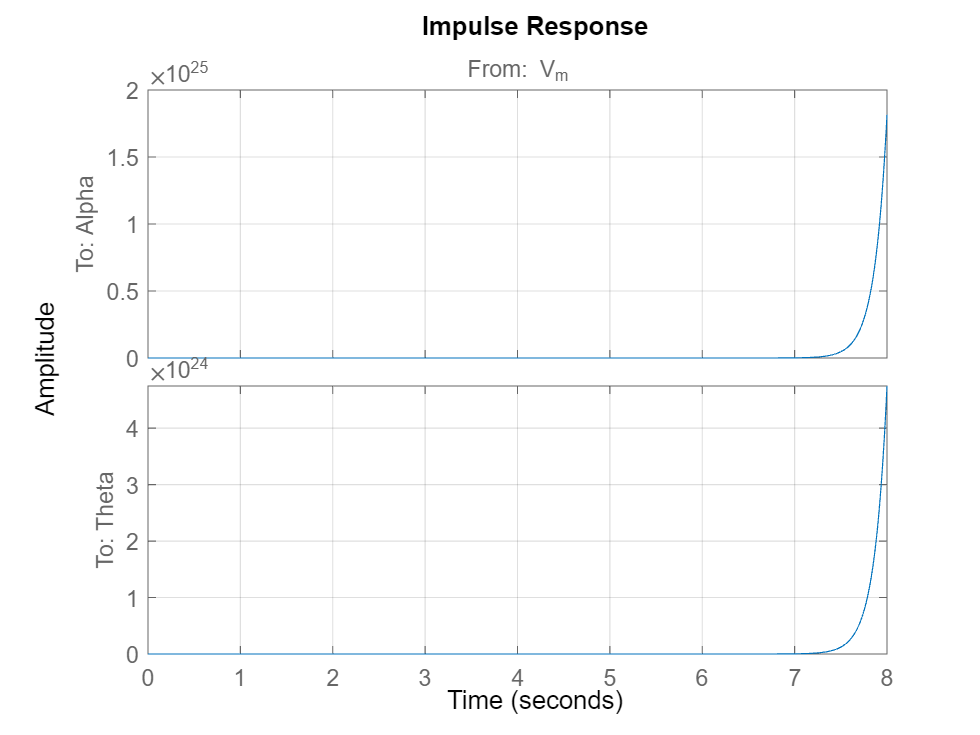

figure;
impulse(lin_system_up_ss);
grid on;

The system in the **upright position** has one unstable pole ( $\Re(p_2) > 0$ ) and therefore, as the simulation proves, it is **unstable**. 

**Downright position:**

roots_down = eig(A_down_val);
disp(roots_down);

   0.0000 + 0.0000i
  -1.6618 + 6.7990i
  -1.6618 - 6.7990i
 -18.3425 + 0.0000i



if any(real(roots_down) > 0)
    disp('  Status: System is UNSTABLE.');
elseif any(real(roots_down) == 0)
    disp('  Status: System is MARGINALLY STABLE.');
else
    disp('  Status: System is STABLE.');
end

  Status: System is MARGINALLY STABLE.


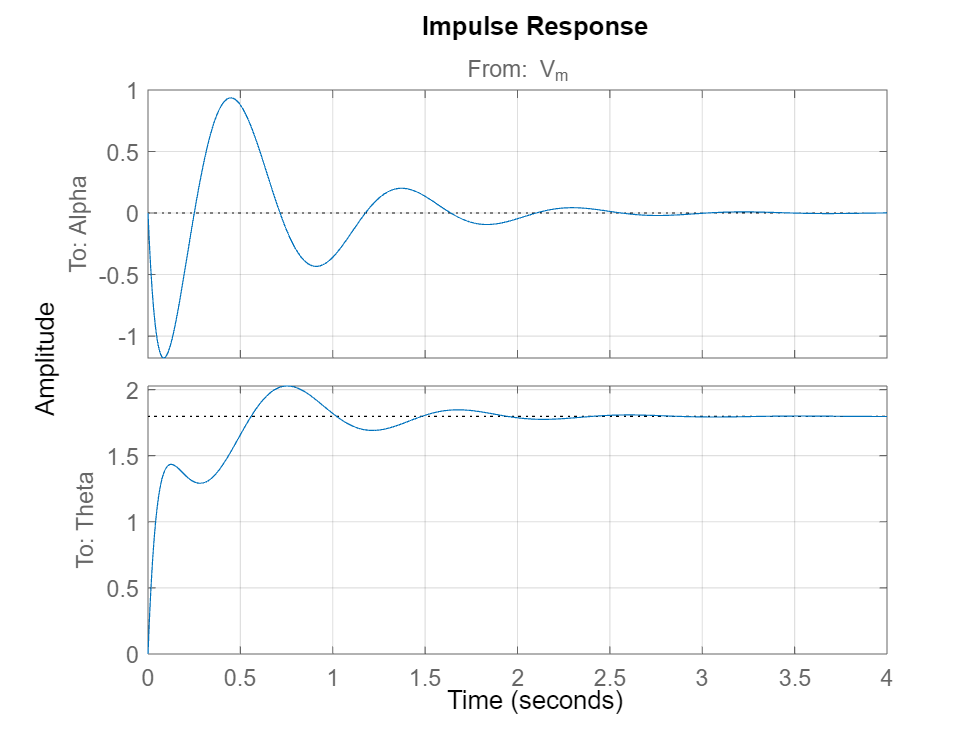


impulse(lin_system_down_ss);
grid on;

The system in **downright** **position** has one marginally stable pole ( $\Re(p_1) = 0$) and therefore, as the simulation proves, it is on the **margin of stability**. This behaviour is caused by the superposition of the stable pendulum poles in the downright position ( $p_2$ , $p_3$ , $p_4$ ), and the pole of the rotary base that acts as an independent astatic system ( $p_1$ ), making the whole system marginaly stable (the impulse response of $\theta$ got stabilized on a nonzero value).

## Control Loop

Since the pendulum in the downards position does not represent interesting control engineering task, for the next section, we will limit the design of the controller only for the upright** working position**.

lin_system_ss = lin_system_up_ss;
A = lin_system_ss.A;
B = lin_system_ss.B;
C = lin_system_ss.C;
D = lin_system_ss.D;

Note: *Technically, many of the following operations should be formulated using the system's transfer functions ( *$tf$* ). However, Matlab allows for interoperability between transfer functions and state-space representations and maintaining the plant models in state-space ( *$ss$* ) form throughout the intermediate algebraic steps offers significant numerical advantages, such as preventing high-order polynomial bloat and eliminating numerical precision errors during pole-zero cancellations.*

### Single PID Controller

A *PID controller* is the most common way to automatically control a system. It continuously calculates an error value ( $e$ ) as the difference between a desired reference ( $r$ ) and a measured variable ( $y$ ), and applies a correction based on three distinct terms: **Proportional (P)**, **Integral (I)**, and **Derivative (D)**.

- **Proportional (P):** Corrects the system based on the **present error **- the bigger the current mistake, the harder it pushes.

- **Integral (I):** Corrects based on the **accumulated past error**, eliminating any lingering, steady-state offset that the P term misses.

- **Derivative (D):** Predicts **future error** by looking at how fast the error is changing, acting like a brake to prevent overshooting the target.

The control action $u$ is mathematically defined as:


$$u(t) = K_p e(t) + K_i \int_{0}^{t} e(\tau) d\tau + K_d \frac{de(t)}{dt}$$


Where $e$ is the error over time, and $K_p$, $K_i$, and $K_d$ are the gains tuning each specific behavior.

PID controller is fundamentally a SISO concept. Therefore, in a single PID loop, we need to choose if we are controlling either the pendulum arm, or the rotary base. This choice is done by the $C$ matrix ( $D$ matrix is usually $0$). Since our matrix $C$ holds multiple outputs, we need to choose one to complete the single PID loop. Instead of going back and modifying the matrix $C$ we can simply select the relevant slice of the state space from our SIMO system.

**Simulink Model of **$SISO_\alpha$** PID Feedback Loop**

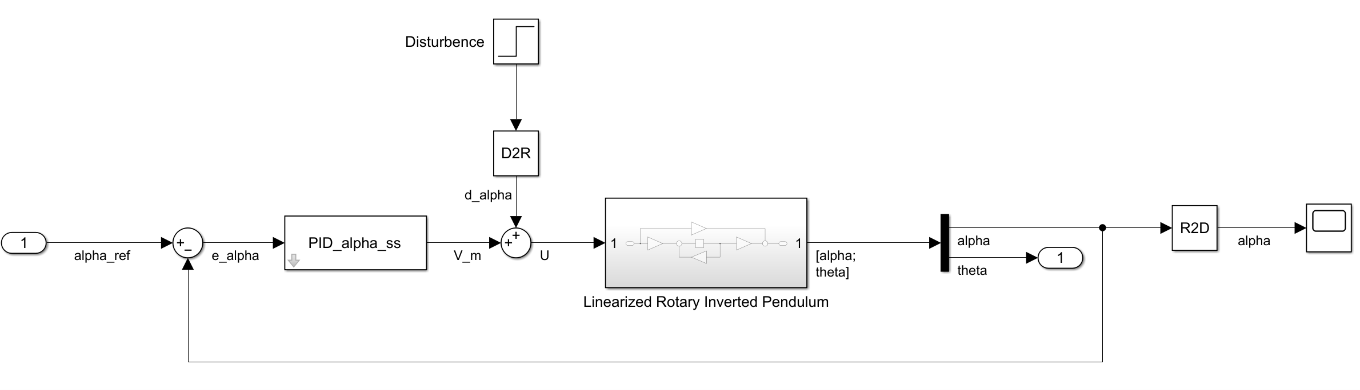

**Controlling only the pendulum arm angle **$\alpha$ ( $SISO_\alpha$ )

SISO_alpha_ss = lin_system_ss(1, 1) % From u -> alpha

SISO_alpha_ss =
 
  A = 
                  Alpha  Alpha_dot      Theta  Theta_dot
   Alpha              0          1          0          0
   Alpha_dot       99.7     -1.137          0     -19.74
   Theta              0          0          0          1
   Theta_dot      58.15    -0.6634          0     -20.53
 
  B = 
                V_m
   Alpha          0
   Alpha_dot  35.49
   Theta          0
   Theta_dot   36.9
 
  C = 
              Alpha  Alpha_dot      Theta  Theta_dot
   Alpha          1          0          0          0
 
  D = 
          V_m
   Alpha    0
 
Continuous-time state-space model.



**Controlling only the rotary base position **$\theta$ ( $SISO_\theta$ )

SISO_theta_ss = lin_system_ss(2, 1) % From u -> theta

SISO_theta_ss =
 
  A = 
                  Alpha  Alpha_dot      Theta  Theta_dot
   Alpha              0          1          0          0
   Alpha_dot       99.7     -1.137          0     -19.74
   Theta              0          0          0          1
   Theta_dot      58.15    -0.6634          0     -20.53
 
  B = 
                V_m
   Alpha          0
   Alpha_dot  35.49
   Theta          0
   Theta_dot   36.9
 
  C = 
              Alpha  Alpha_dot      Theta  Theta_dot
   Theta          0          0          1          0
 
  D = 
          V_m
   Theta    0
 
Continuous-time state-space model.



Note: *Notice that the two state spaces differ only in the *$C$ matrix.

Lets first choose to control the pendulum arm.

#### Controlling the Pendulum Arm with a Single PID

**Tuning the PID**

To tune the PID we can use the Matlab's patented algorithm *pidtune()*.

Note: *To satisfy physical causality laws and ensure numerical realizability, the ideal PID controller structure is replaced with a filtered PID (PIDF) architecture. By doing so, the system remains proper (the nominator is a polynomial of lower or equal order as the denominator) and more faithfuly represents physical hardware.*

PID_alpha_ss = pidtune(SISO_alpha_ss, 'PIDF');
disp('SISO Alpha PID controller: ')

SISO Alpha PID controller: 


disp(PID_alpha_ss);

  pid with properties:

              Kp: 138.2496
              Ki: 1.6362e+03
              Kd: 2.6635
              Tf: 9.3622e-04
        IFormula: ''
        DFormula: ''
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



PID_alpha_tf = tf(PID_alpha_ss)

PID_alpha_tf =
 
  2983 s^2 + 1.493e05 s + 1.748e06
  --------------------------------
            s^2 + 1068 s
 
Continuous-time transfer function.



**PID Open-Loop System (OL)**

SISO_alpha_OL_ss = SISO_alpha_ss * PID_alpha_ss;  % Note: The order of multiplication (sys * PID) is important. The order (PID * sys) is not correct. (Related to matrix multiplication of MIMO)
SISO_alpha_OL_tf = tf(SISO_alpha_OL_ss)

SISO_alpha_OL_tf =
 
  From input to output "Alpha":
    1.059e05 s^3 + 5.299e06 s^2 + 6.203e07 s - 1.444e-07
  ---------------------------------------------------------
  s^5 + 1090 s^4 + 2.305e04 s^3 - 9.644e04 s^2 - 9.598e05 s
 
Continuous-time transfer function.



**PID Closed-Loop System (CL)**

SISO_alpha_CL_ss = feedback(SISO_alpha_OL_ss, 1);
SISO_alpha_CL_tf = tf(SISO_alpha_CL_ss)

SISO_alpha_CL_tf =
 
  From input to output "Alpha":
          1.059e05 s^3 + 5.299e06 s^2 + 6.203e07 s + 5.233e-07
  ---------------------------------------------------------------------
  s^5 + 1090 s^4 + 1.289e05 s^3 + 5.203e06 s^2 + 6.107e07 s - 1.764e-06
 
Continuous-time transfer function.



**PID Stability analysis of CL based of OL**

To assess the controller and system synergy, we can conduct a frequency response analysis of the open loop using diagrams such as Bode or Nyquist (or Matlab's margin()).

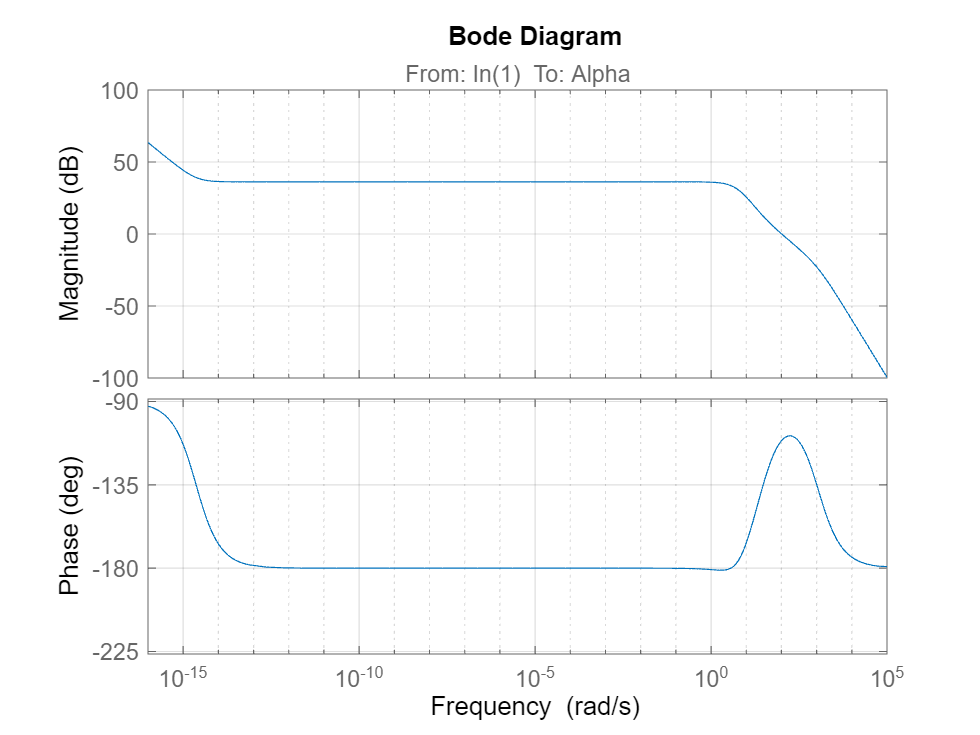

figure;
bode(SISO_alpha_OL_ss);
grid on;

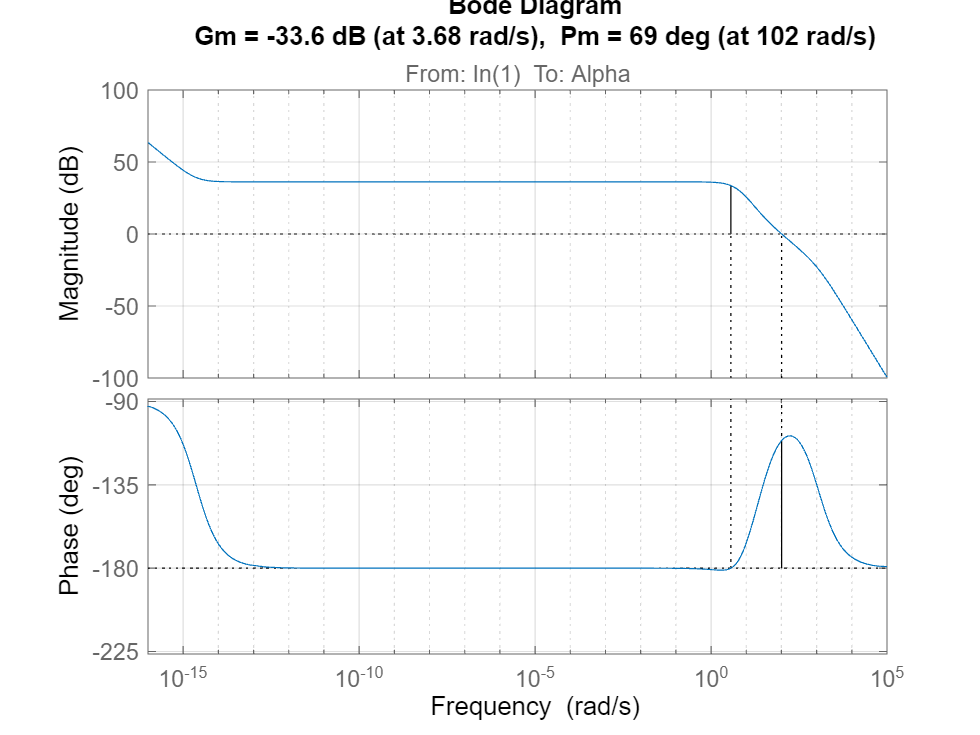

margin(SISO_alpha_OL_ss);
grid on;

The Bode analysis generated by the *margin()* command indicates a negative Gain Margin of $-33.6\text{ dB}$. However, because the **system is unstable in the upright position, the open-loop cannot stabilize it by itself **and therefore, the **open-loop system is inherently unstable too.** **Standard classical margin interpretations are unreliable in this context**. Therefore, the margins shown in *margin *plot **cannot be used to definitively determine closed-loop stability.** 

We can confirm the unstability of the open-loop by inspecting the open-loop poles

SISO_alpha_OL_poles = pole(SISO_alpha_OL_ss)

SISO_alpha_OL_poles = 1.0e+03 *

   -0.0238
    0.0073
   -0.0051
         0
   -1.0681
         0


if any(real(SISO_alpha_OL_poles) > 0)
    disp('Status: System is UNSTABLE.');
elseif any(real(abs(SISO_alpha_OL_poles)) <= 0)
    disp('Status: System is MARGINALLY STABLE.');
else
    disp('Status: System is STABLE.');
end

Status: System is UNSTABLE.


Here we can see that the open-loop has **one unstable pole** ( $\Re(p_2) > 0$ ), therefore it is unstable.

**To reliably judge the closed-loop stability based on the unstable-open loop, we must rely entirely on the Nyquist stability criterion:**

Deffinition: *"The number of unstable poles of the closed-loop ( *$Z$ *) is given by the number of unstable poles of the open-loop ( *$P$ ) *plus the number of encirclements of the critical point ( *$N$ *) ."*


$$Z = N + P$$


Note: *The sign of *$N$ depends on the direction of the encirclement. Clockwise counts as positive encirclement and anti-clockwise counts as negative. This means that anti-clockwise encirclements can actually help to eliminate unstable poles of the open-loop.

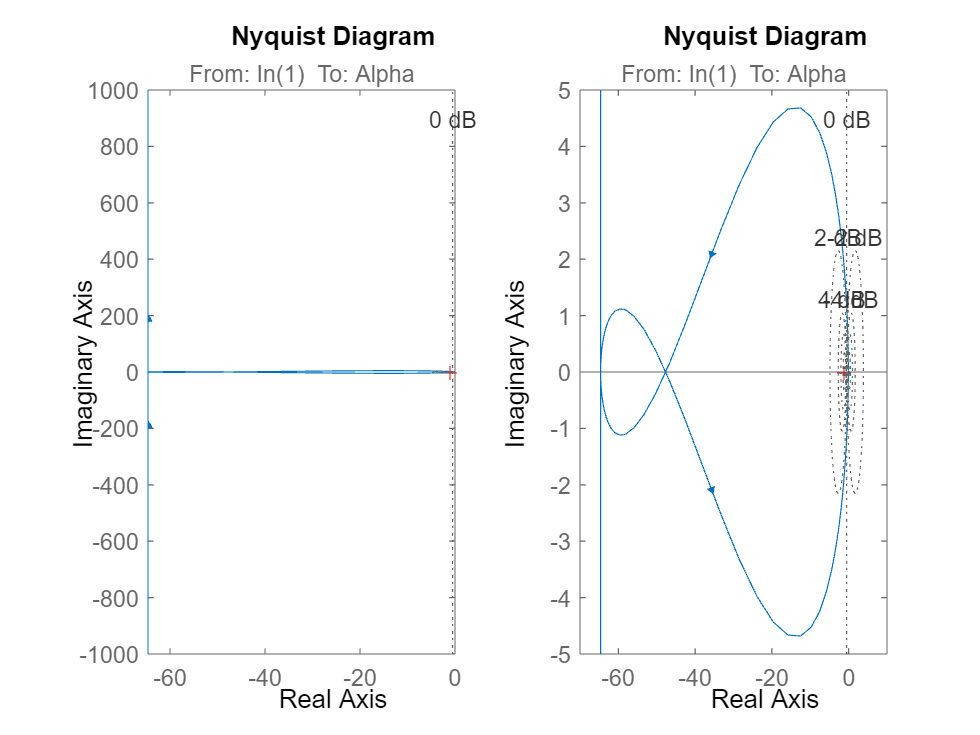

opts = nyquistoptions;
opts.ShowFullContour = 'off';  % Use opts in Nyquist if desired to remove negative frequencies

figure;
subplot(1, 2, 1);
nyquist(SISO_alpha_OL_ss);
grid on;
subplot(1, 2, 2);
nyquist(SISO_alpha_OL_ss);
xlim([-70, 10]);
ylim([-5, 5]);
grid on;

upon inspecting the poles of the open-loop system, we can notice that not only does the system have one unstable pole ( $p_2 \rightarrow P = 1$ ) , but it also has two marginally stable poles ( $p_4 = p_6 = 0$ ) representing two integrators (astatic system). In the Nyquist diagram, these integrators manifest into two "ends" of the frequency response shooting off to $+\infty$ for positive low frequencies ( $\omega \rightarrow 0$ ) and $-\infty$ for negative low frequencies ( $-\omega \rightarrow 0$ ). These "loose ends" are actually connected at infinity, forming an enclosed loop that does encircle the critical point exactly once anti-clockwise ( $N = -1$ ). Therefore, based on the Nyquist stability criterion, we can conclude that the closed-loop system does not have any strictly unstable poles ( $Z = 0$ ). While we now know that the closed-loop will not be strictly unstable, due to the presence of the marginally stable poles of the open-loop, we still have to consider the possibility of the closed-loop system inheriting open-loop marginal stability. One way to confirm the marginal stability would be if the frequency response passed directly through the critical point [-1, j0]. Since that is not the case in our plot, we should resort to another strategy to assess the true nature of the closed-loop system.

**PID Stability analysis of CL based of CL**

Since the frequency response analysis with Bode or Nyquist diagrams tells us how the output produced by the open-loop would affect the system if introduced as feedback, it loses its meaning when applied to an already closed feedback loop. Therefore, to distinguish between a stable and a marginally stable closed-loop system based purely on closed-loop, we must directly inspect the poles of the closed loop.

SISO_alpha_CL_poles = pole(SISO_alpha_CL_ss)

SISO_alpha_CL_poles = 1.0e+02 *

  -9.6121 + 0.0000i
  -0.5428 + 0.1508i
  -0.5428 - 0.1508i
  -0.2002 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


% One of the poles is, perhaps because of a numerical floating-point precision limitations, not exactly 0 - introducing tolerance "tol"
tol = 1e-5;

if any(real(SISO_alpha_CL_poles) > tol)
    disp('Status: System is UNSTABLE.');
elseif any(real(abs(SISO_alpha_CL_poles)) <= tol)
    disp('Status: System is MARGINALLY STABLE.');
else
    disp('Status: System is STABLE.');
end

Status: System is MARGINALLY STABLE.


Here we obtain a final and **definite** answer: the **closed-loop** system is **marginally stable**. 

As we can see, directly inspecting the poles of the closed loop is a much faster and more direct approach, which naturally begs the question of why we utilize the Nyquist stability criterion in the first place. One of the core benefits of the Nyquist stability criterion, as opposed to direct pole identification, is that it does not strictly require a mathematical model of the system. Instead, we can simply measure the open-loop frequency response experimentally and evaluate **closed-loop** stability without ever having to laboriously model the plant (which is often one of the most challenging tasks in control engineering). Another major benefit of these graphical diagrams over direct pole identification is the ability to easily judge **closed-loop** **robustness** and its **safety** **margins**.

**PID CL Simulations**

First, we can confirm the unstability of the open loop

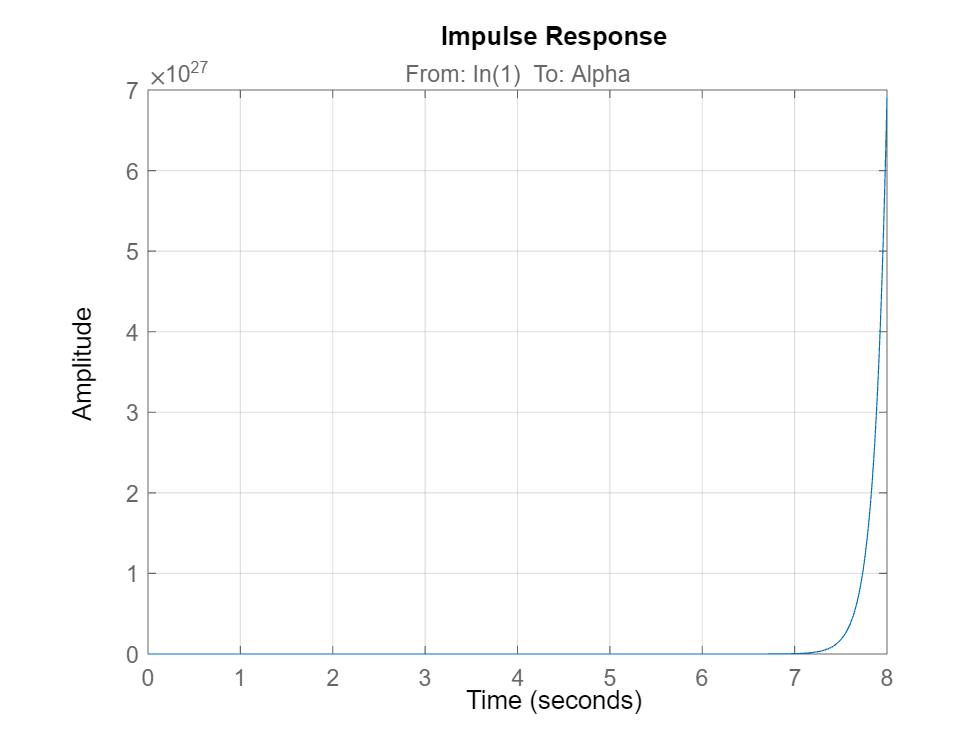

figure;
impulse(SISO_alpha_OL_ss);
grid on;

Now, we can test the impulse response of our closed loop

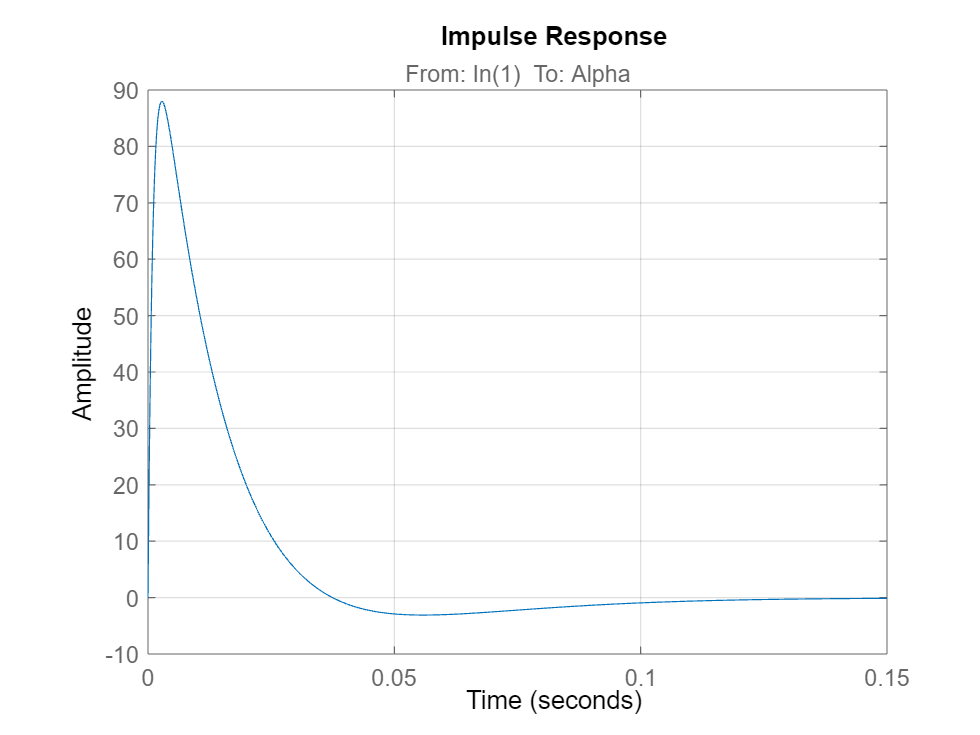

figure;
impulse(SISO_alpha_CL_ss);
grid on;

The PID controller effectively eliminates any disturbances while keeping the pendulum in the upright position.

Since the stability analysis revealed, that the closed loop system is marginally stable, we could assume that a step response would look like a ramp. However, when inspected, the step response suprisingly shows a stable control of the pendulums arm at an angle $\alpha_{cconst}$ (dictated by the step function $\alpha_{const} = 1~rad$).

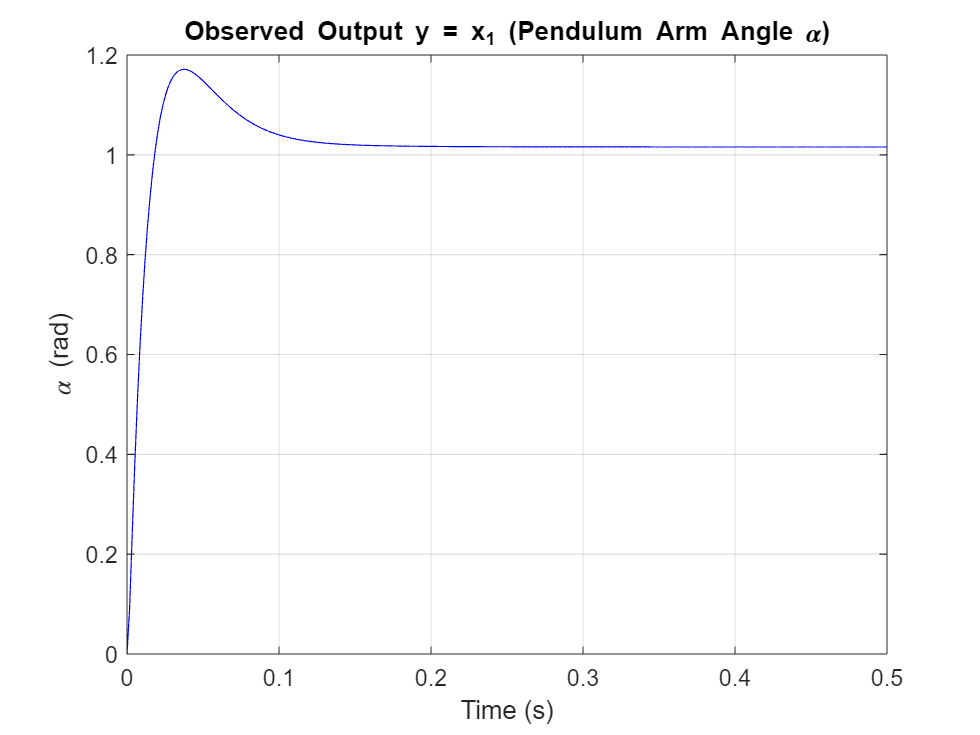

duration = 0.5; % [s]
[y, t, x] = step(SISO_alpha_CL_ss, duration);

figure;
plot(t, y, 'b');
title('Observed Output y = x_1 (Pendulum Arm Angle \alpha)');
xlabel('Time (s)');
ylabel('\alpha (rad)');
grid on;

This is caused by the fact, that we are actually observing only the angle of the pendulums arm $\alpha$ , which was indeed stabilized. However, we have completely neglected the rotary base. Lets see what is happening to the "hidden state" of the rotary base while we are stabilising the pendulum.

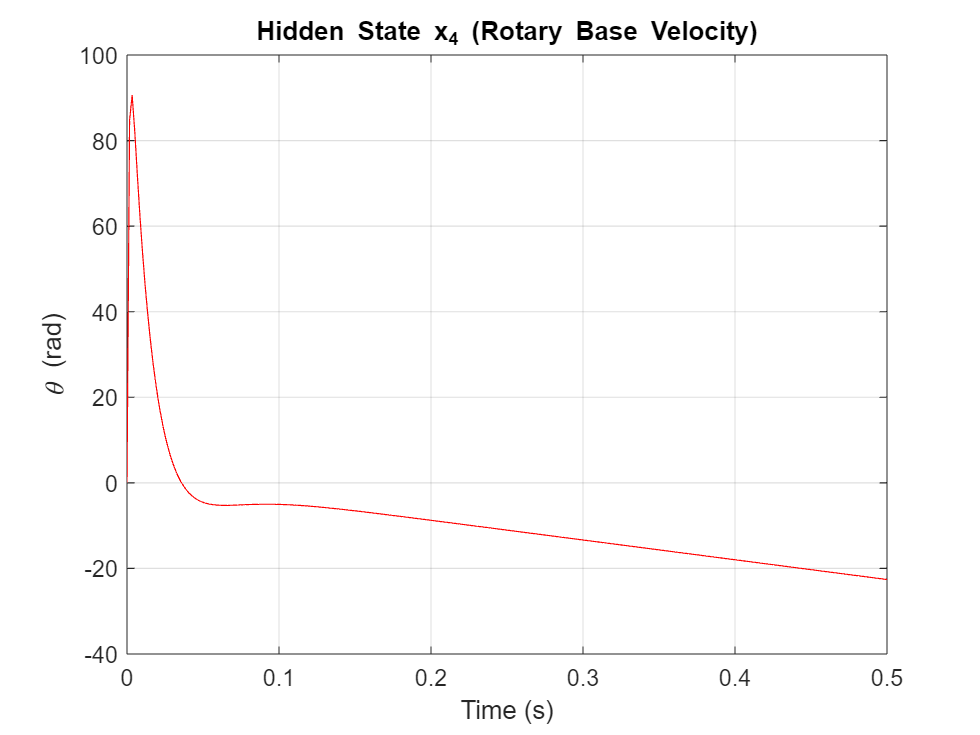

figure;
plot(t, x(:, 4), 'r'); % Slicing the 4th column for x_4 (theta_dot)
title('Hidden State x_4 (Rotary Base Velocity)');
xlabel('Time (s)');
ylabel('\theta (rad)');
grid on;

As we can see, in order for the controller to maintain the pendulum at an angle $\alpha_{const}$, the rotary base needs to keep constantly accelerating to compensate for the gravity acceleration. **This is the root of the marginal stability of the whole system**.

Lets test the impulse response of our closed loop, but this time lets look at both the pendulum arm and the rotary base at the same time.

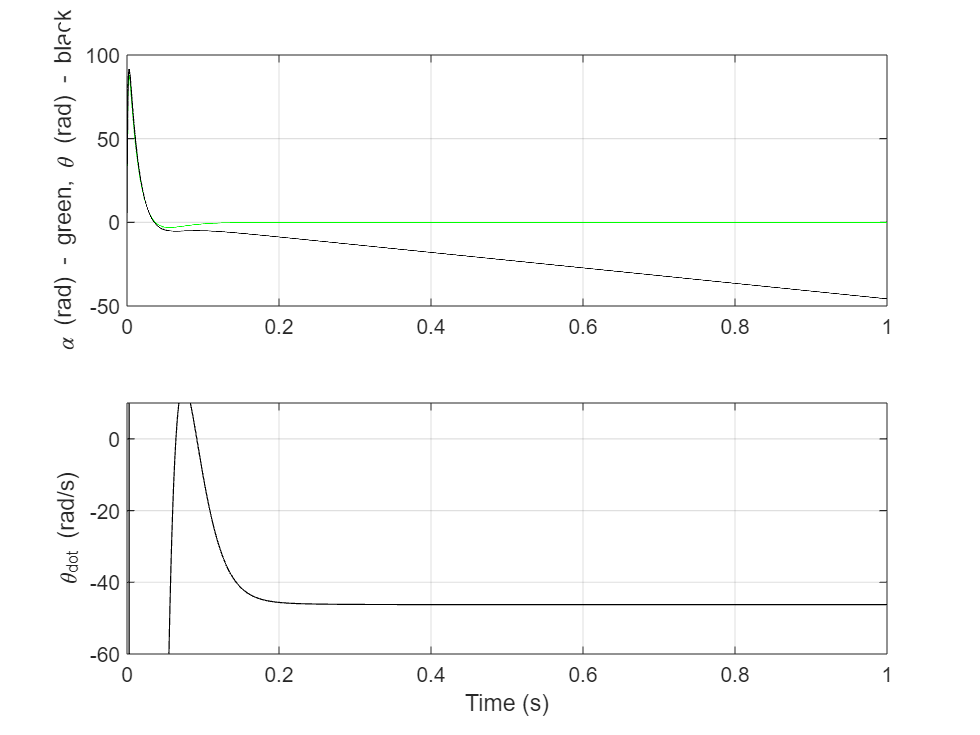

duration = 1;
[y, t, x] = impulse(SISO_alpha_CL_ss, duration);

figure;
title('Observed Output y = x_1 (Pendulum Arm Angle \alpha) and the Hidden State x_3 (Rotary Base \theta)');
subplot(2 , 1, 1)
plot(t, y, 'g');
hold on;
plot(t, x(:, 3), 'black'); % Slicing the 3rd column for x_3
hold off;
ylabel('\alpha (rad) - green, \theta (rad) - black');
grid on;
subplot(2, 1, 2);
plot(t, x(:, 4), 'black'); % Slicing the 4th column for x_4
hold off;
xlabel('Time (s)');
ylabel('\theta_{dot} (rad/s)');
xlim([0, t(end)]);
ylim([-60, 10]);
grid on;

This impulse response reveals another reality of this **marginally stable** system. While the control loop successfully averts the effect of the **impulse** on the pendulum arm, the controller's integrator accumulates a non-zero constant value. This leads to a constant velocity drift of the rotary base while the pendulum arm remains stabilized in the upright position. Note that the velocity of the rotary base itself ( $\dot{\theta}$ ), in contrast to its acceleration ( $\ddot{\theta}$ ), does not destabilize the pendulum arm due to the lack of induced inertial forces once a constant speed is reached.

Lets do the exact same control loop but this time observe only the angle of the rotary base $\theta$ ( $SISO_\theta$ )

#### Controlling the Rotary Base with a Single PID

**Tuning the PID**

PID_theta_ss = pidtune(SISO_theta_ss, 'PIDF'); % F stands for Filter (to keep the system proper)
disp('SISO Theta PID controller: ')

SISO Theta PID controller: 


disp(PID_theta_ss);

  pid with properties:

              Kp: 4.7853e+05
              Ki: 2.2011e+08
              Kd: 255.5446
              Tf: 1.8923e-05
        IFormula: ''
        DFormula: ''
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



PID_theta_tf = tf(PID_theta_ss)

PID_theta_tf =
 
  1.398e07 s^2 + 2.551e10 s + 1.163e13
  ------------------------------------
            s^2 + 5.285e04 s
 
Continuous-time transfer function.



**Open-Loop System (OL)**

SISO_theta_OL_ss = SISO_theta_ss * PID_theta_ss;
SISO_theta_OL_tf = tf(SISO_theta_OL_ss)

SISO_theta_OL_tf =
 
  From input to output "Theta":
  5.16e08 s^4 + 9.416e11 s^3 + 4.297e14 s^2 + 1.732e14 s - 1.879e16
  -----------------------------------------------------------------
   s^6 + 5.287e04 s^5 + 1.145e06 s^4 - 4.728e06 s^3 - 4.749e07 s^2
 
Continuous-time transfer function.



**Closed-Loop System (CL)**

SISO_theta_CL_ss = feedback(SISO_theta_OL_ss, 1);
SISO_theta_CL_tf = tf(SISO_theta_CL_ss)

SISO_theta_CL_tf =
 
  From input to output "Theta":
             5.16e08 s^4 + 9.416e11 s^3 + 4.297e14 s^2 + 1.732e14 s - 1.879e16
  ---------------------------------------------------------------------------------------
  s^6 + 5.287e04 s^5 + 5.172e08 s^4 + 9.416e11 s^3 + 4.297e14 s^2 + 1.732e14 s - 1.879e16
 
Continuous-time transfer function.



**PID Stability analysis of CL**

SISO_theta_CL_poles = pole(SISO_theta_CL_ss)

SISO_theta_CL_poles = 1.0e+04 *

   -4.0732
   -0.9943
   -0.1471
   -0.0720
    0.0006
   -0.0007


tol = 1e-5;

if any(real(SISO_theta_CL_poles) > tol)
    disp('Status: System is UNSTABLE.');
elseif any(real(abs(SISO_theta_CL_poles)) <= tol)
    disp('Status: System is MARGINALLY STABLE.');
else
    disp('Status: System is STABLE.');
end

Status: System is UNSTABLE.


Since controlling the rotary base position $\theta$ seems rather simpler than controlling the pendulum arm in the upright position, the stability analysis conclusion is rather surprising. While the pendulum arm control loop was at least marginably stable, the rotary base control loop is completely unstable. Lets look at the simulations to understand what is actually happening.

**PID CL Simulations**

Again we can test the step response for the observed output and the hidden state

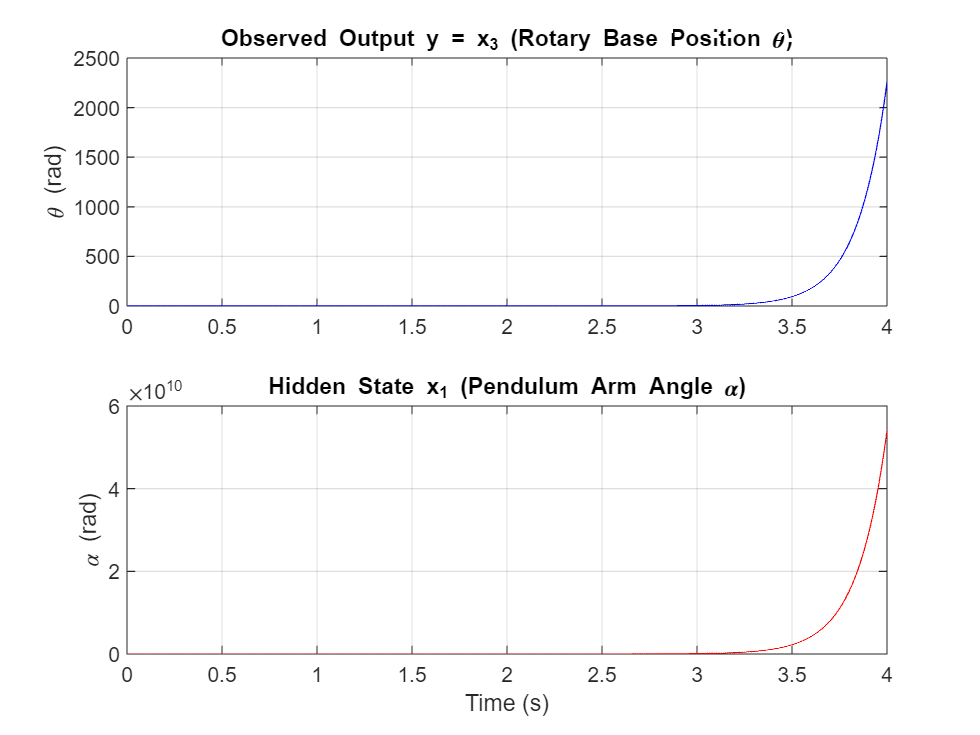

duration = 4; % [s]
[y, t, x] = step(SISO_theta_CL_ss, duration);

figure;
subplot(2, 1, 1);
plot(t, y, 'b');
title('Observed Output y = x_3 (Rotary Base Position \theta)');
ylabel('\theta (rad)');
grid on;
subplot(2, 1, 2);
plot(t, x(:, 1), 'r'); % Slicing the 1st column for x_1
title('Hidden State x_1 (Pendulum Arm Angle \alpha)');
xlabel('Time (s)');
ylabel('\alpha (rad)');
grid on;

Here, we can see that by changing the observed output, we completely lose the capability to control this system. By slightly moving the rotary base with the step response, the pendulum arm falls down. Since the closed loop does not observe the angle of the pendulum arm, it can only react to the resulting reaction torques exerted on the rotary base. Furthermore, because this control loop is evaluated on a **linearized** model, it fails to account for the cyclic, sinusoidal nature of the real nonlinear pendulum. Therefore, the linearized gravity term accelerates the arm toward infinity instead of swinging back and forth, completely overpowering any attempts to stabilize the rotary base. One might intuitively assume that operating on a nonlinear system would allow the pendulum arm to naturally settle into its stable downright equilibrium point while the base stabilizes**. **However, due to the unobserved cross-coupled dynamics, any movement of the base injects unmanaged energy into the pendulum, causing growing oscillations that ultimately destabilize the entire system regardless of the pendulum's orientation.

Due to the **underactuated** and **cross-coupled** nature of the rotary inverted pendulum, a classical **single-loop PID controller is only capable of, at best, achieving marginal stability regardless of the parameter tuning**. To achieve full asymptotic stability (forcing both the pendulum angle to zero and the rotary base position to any chosen setpoint), a multi-variable control strategy such as Cascaded PID or Full-State Feedback should be utilized.

### Multiple PID Controllers - Cascade Control Loop

By wrapping the pendulum arm feedback loop ( $SISO_\alpha$ ) with rotary base feedback loop ( $SISO_\theta$ ), we create a *Cascade PID Control Loop*. This allows us to chain two SISO control loops into one SIMO loop. The **inner closed loop** with the PID controller and the rotary inverted pendulum effectively turns into a new system - the **inner system **that is in turn controlled by the outer PID controller. The Cascade PID Control Loop consits of:

the **Outer Loop**

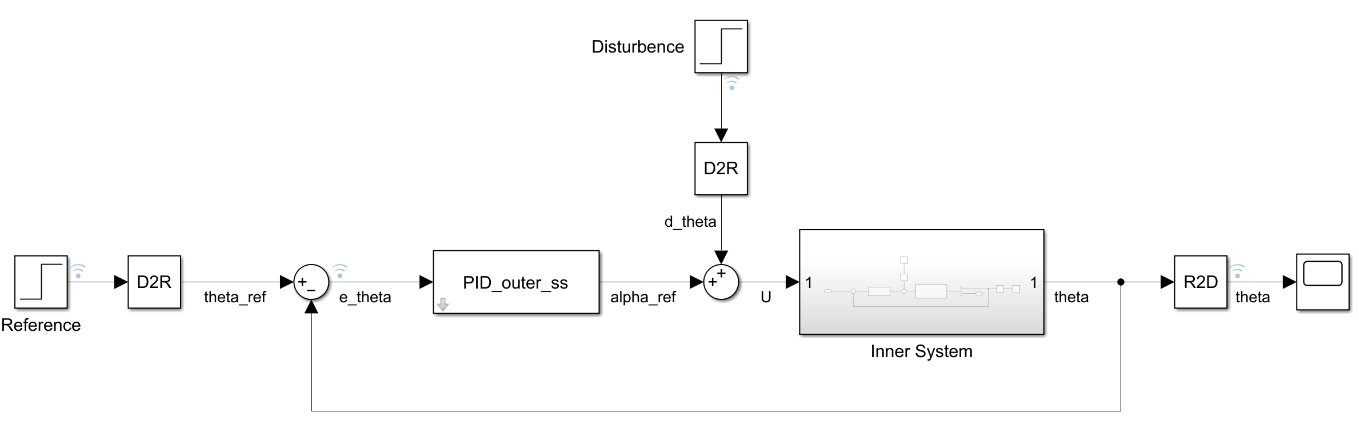

and inside of the Inner System, the **Inner Loop**

Note: *The Inner Loop block is identical with the loop shown above in the section "Simulink Model of SISO PID Feedback Loop".*

Theoretically, we can make as much cascade layers as we can, possibly covering all states. The only **important rule is that the dynamics of the control loop layers should go from fast to slow**. This is the reason why I have chosen the inner loop to be the $SISO_\alpha$ as it is dynamics are fundamentally faster than the $SISO_\theta$ dynamics. Swapping the order would likely not lead to a successfull stable controller design.

#### Modeling the Inner System

**Tracing the Inner Closed Loop (from **$\alpha_{ref}$** to **$U$**)**

let's trace the signal to find the transfer function from the input reference ( $\alpha_{ref}$ ) to the motor voltage ( $U$ ) (ignoring the disturbance):

- The error signal is: $e_{\alpha} = \alpha_{ref} - \alpha$

- The voltage out of the PID is: $U = PID_{\alpha} \cdot e_{\alpha}$

- The physical pendulum angle is: $\alpha = SISO_{\alpha} \cdot U$

Substitute 3 into 1 and then into 2:


$$U = PID_{\alpha} \cdot (\alpha_{ref} - SISO_{\alpha} \cdot U)$$


Now, solve for the closed-loop transfer function $\frac{U}{\alpha_{ref}}$:


$$U + PID_{\alpha} \cdot SISO_{\alpha} \cdot U = PID_{\alpha} \cdot \alpha_{ref}$$



$$\frac{U}{\alpha_{ref}} = \frac{PID_{\alpha}}{1 + PID_{\alpha} \cdot SISO_{\alpha}}$$


This, in Matlab, translates into *feedback(*$PID_\alpha$, $SISO_\alpha$).

inner_SISO_alpha_CL_ss = feedback(PID_alpha_ss, SISO_alpha_ss);
inner_SISO_alpha_CL_tf = tf(inner_SISO_alpha_CL_ss)

inner_SISO_alpha_CL_tf =
 
  2983 s^5 + 2.139e05 s^4 + 4.716e06 s^3 + 2.183e07 s^2 - 2.905e08 s - 1.57e09
  ----------------------------------------------------------------------------
     s^5 + 1090 s^4 + 1.289e05 s^3 + 5.203e06 s^2 + 6.107e07 s + 7.499e-07
 
Continuous-time transfer function.



**Turning the Inner Loop **$SISO_\alpha$ **into the Inner System **$SISO_{\theta, inner}$

The inner loop signal chain is in terms of input voltage $V_m$ and the output pendulum arm angle $\alpha$ ( $SISO_\alpha$ ). To integrate it into the outer loop, we need to translate the signal chain from rotary base position ( $\theta$ ) to pendulum arm angle ( $\alpha$ ), with the *"input to rotary base position*"* ( *$u \rightarrow \theta$*) *transfer function $SISO_\theta$ chained in seiries with the inner closed loop.

inner_SISO_theta_ss = minreal(SISO_theta_ss * inner_SISO_alpha_CL_ss);  % Reduce bloated polynomials with minreal

4 states removed.


% We could teoretically achieve the same outcome with this approach:

% inner_CL_ss = feedback(PID_alpha_ss * SISO_alpha_ss, 1);
% SISO_alpha_theta_ss = SISO_theta_ss / SISO_alpha_ss;
% inner_system_ss = minreal(SISO_alpha_theta_ss * inner_CL_ss);

% However, due to computational innaccuracies of the fraction
% SISO_alpha_theta_ss, this approach fails to produce the same outcome as
% the code above (notice minreal removed 9 states as opposed to the 4 states from the previous approach).

inner_SISO_theta_tf = tf(inner_SISO_theta_ss)

inner_SISO_theta_tf =
 
  From input to output "Theta":
            1.101e05 s^4 + 5.565e06 s^3 + 6.243e07 s^2 - 2.09e08 s - 2.823e09
  -------------------------------------------------------------------------------------
  s^6 + 1090 s^5 + 1.289e05 s^4 + 5.203e06 s^3 + 6.107e07 s^2 + 2.402e-05 s - 0.0003245
 
Continuous-time transfer function.



As we can see, the inner system is rather complex combination of the PID controller and the original system with its own set of state variables. These state variables no longer represent the original set of  4 state variables ($x_1 = \alpha$, $x_2 = \dot{\alpha}$, $x_3 = \theta$, $x_4 = \dot{\theta}$).

**Tuning the PID**

For the inner feedback loop, we can directly use the $PID_\alpha$ tuned above, as these two control loops are identical. However for the outer controller, we can no longer use the $PID_\theta$ directly. We have to tune a new controller on the inner system. The outer PID controller needs to be generally slower than the inner PID controller and for that reason we help the *pidtune()* function by providing rather slow target crossover frequency $w_c = 3~rad/s$ (this number was selected experimentally).

PID_outer_ss = pidtune(inner_SISO_theta_ss, 'PIDF', 3);
disp('Outer Closed Loop PID controller: ')

Outer Closed Loop PID controller: 


disp(PID_outer_ss);

  pid with properties:

              Kp: -0.0098
              Ki: -2.1682e-04
              Kd: -0.0577
              Tf: 0.1570
        IFormula: ''
        DFormula: ''
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



PID_outer_tf = tf(PID_outer_ss)

PID_outer_tf =
 
  -0.377 s^2 - 0.0625 s - 0.001381
  --------------------------------
           s^2 + 6.369 s
 
Continuous-time transfer function.



**Outer Closed-Loop System**

outer_SISO_theta_CL_ss = feedback(PID_outer_ss * inner_SISO_theta_ss, 1);
outer_SISO_theta_CL_tf = tf(outer_SISO_theta_CL_ss)

outer_SISO_theta_CL_tf =
 
          -4.15e04 s^6 - 2.105e06 s^5 - 2.388e07 s^4 + 7.486e07 s^3 + 1.077e09 s^2 + 1.767e08 s + 3.898e06
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 1096 s^7 + 9.437e04 s^6 + 3.919e06 s^5 + 7.032e07 s^4 + 4.638e08 s^3 + 1.077e09 s^2 + 1.767e08 s + 3.898e06
 
Continuous-time transfer function.



Notice that we have turned the fundamentally $SIMO$ system into $SISO_\theta$ system with integrated "hidden" inner system $SISO_\alpha$. 

**Stability Analysis**

cascade_poles = pole(outer_SISO_theta_CL_ss)

cascade_poles = 1.0e+03 *

  -1.0062 + 0.0000i
  -0.0294 + 0.0298i
  -0.0294 - 0.0298i
  -0.0000 + 0.0000i
  -0.0001 + 0.0000i
  -0.0050 + 0.0014i
  -0.0050 - 0.0014i
  -0.0210 + 0.0000i


if any(real(cascade_poles) > 0)
    disp('  Status: System is UNSTABLE.');
elseif any(real(cascade_poles) == 0)
    disp('  Status: System is MARGINALLY STABLE.');
else
    disp('  Status: System is STABLE.');
end

  Status: System is STABLE.


We have successfully turned the marginal stability of $SISO_\alpha$ and the unstability of the $SISO_\theta$ into a stable system.

Note:* So far, I have been inspecting the system poles directly to judge the stability. However, there is also a native Matlab's function isstable(sys_ss) that we could conveniently use instead. It is important to note that the isstable() output is binary (stable: 1, unstable: 0) and therefore it conservatively flags marginally stable systems as unstable. Since from this point on, we do not expect marginal stability of the system, for simplicity, I will use the isstable() function.*

#### Cascade PID Control Simulation (Linearized Model)

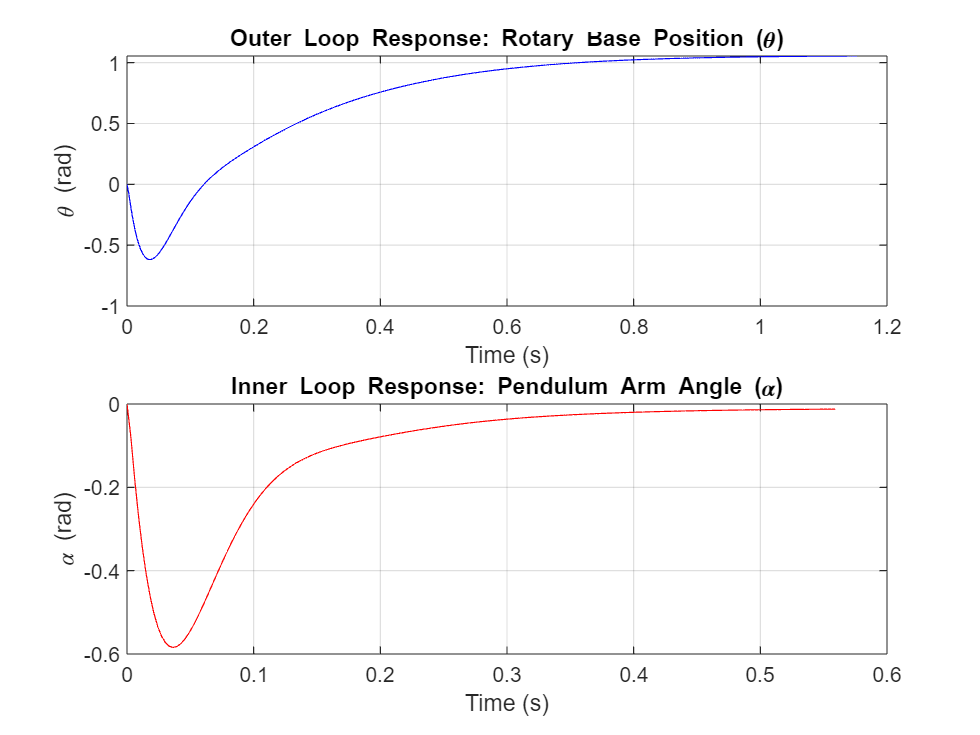

% Since the state variables got scrambled inside Matlabs calculations, we
% can no longer simply slice the SISO theta step function state varaibles to pick the
% inner state (alpha)

% Signal path theta_ref -> alpha
Forward_to_u = inner_SISO_alpha_CL_ss * PID_outer_ss;
Forward_to_alpha = SISO_alpha_ss * Forward_to_u;
outer_SISO_alpha_CL_ss = feedback(Forward_to_alpha, 1);

duration = NaN; % [s]
[y_theta, t_theta] = step(outer_SISO_theta_CL_ss, duration);
[y_alpha, t_alpha] = step(outer_SISO_alpha_CL_ss, duration);

figure('Name', 'Cascade PID Control Performance');
subplot(2, 1, 1);
plot(t_theta, y_theta, 'b');
title('Outer Loop Response: Rotary Base Position (\theta)');
xlabel('Time (s)');
ylabel('\theta (rad)');
grid on;
subplot(2, 1, 2);
plot(t_alpha, y_alpha, 'r');
title('Inner Loop Response: Pendulum Arm Angle (\alpha)');
xlabel('Time (s)');
ylabel('\alpha (rad)');
grid on;

step_info = stepinfo(y_theta, t_theta);
tau_theta = step_info.SettlingTime

tau_theta = 0.8576

Finally, we have successfully designed a control loop that can command the rotary base to any position $\theta_{const}$ while keeping the pendulum in the upright position.

upon inspection, we can also notice that the rotary base has to first move in the opposite direction of the reference to later successfully stabilize on the reference value. Physically, this means that the rotary base has to tilt the pendulum forward before moving it in that direction without losing control over it. Systems behaving this way are called **non-mimal phase systems** and mathematically manifests as **zeros in the right plane of the complex s-domain** ( $\Re(z) > 0$ ) .

We can prove this by inspecting the zeros of this system:

outer_CL_theta_zeros = zero(outer_SISO_theta_CL_ss)

outer_CL_theta_zeros =   -31.3791
  -18.6700
    6.3710
   -6.8704
   -0.1395
   -0.0263


And as we can see, there is indeed one zero ( $z_3$ ) in the right plane of the complex s-domain.

#### Cascade PID Control Simulation (Nonlinear Model)

So far, we have conducted the simulations and analysis on the linearized model of the rotary inverted pendulum system. However, pure Matlab - unlike Simulink - does not natively support the nonlinear system simulations as it does with the linear systems (*step() etc. *work only with linear models). Since we already have the models in Simulink, we can conviniently use them to test the control loop on the nonlinear system by simply replacing the linearized model in the inner loop with the nonlinear model (without changing anything else).

**Simulink model of the Nonlinear System**

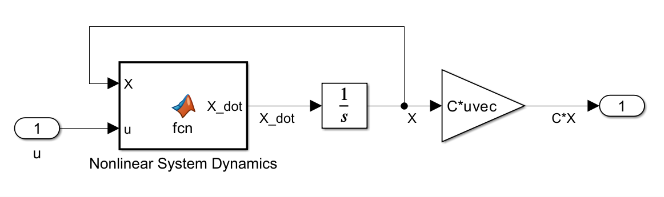

Note: *The function block holds the same State-Space equations of the system dynamics derived in the "Mathematical Model of Rotary Inverted Pendulum" section.*

**Simulink model of the Inner Loop (Nonlinear Model)**

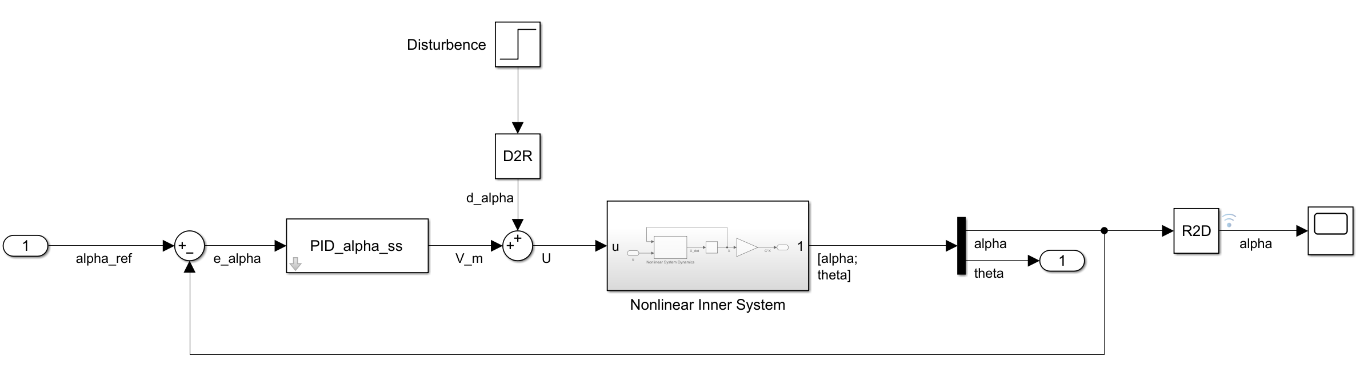

Note: *The outer loop for the nonlinear model control loop is identical to the outer loop for the linear model control loop.*

Since we already have the Simulink models prepared, we can use them to simulate the system behaviour and evaluate (Matlab doesn't support nonlinear state-space representations).

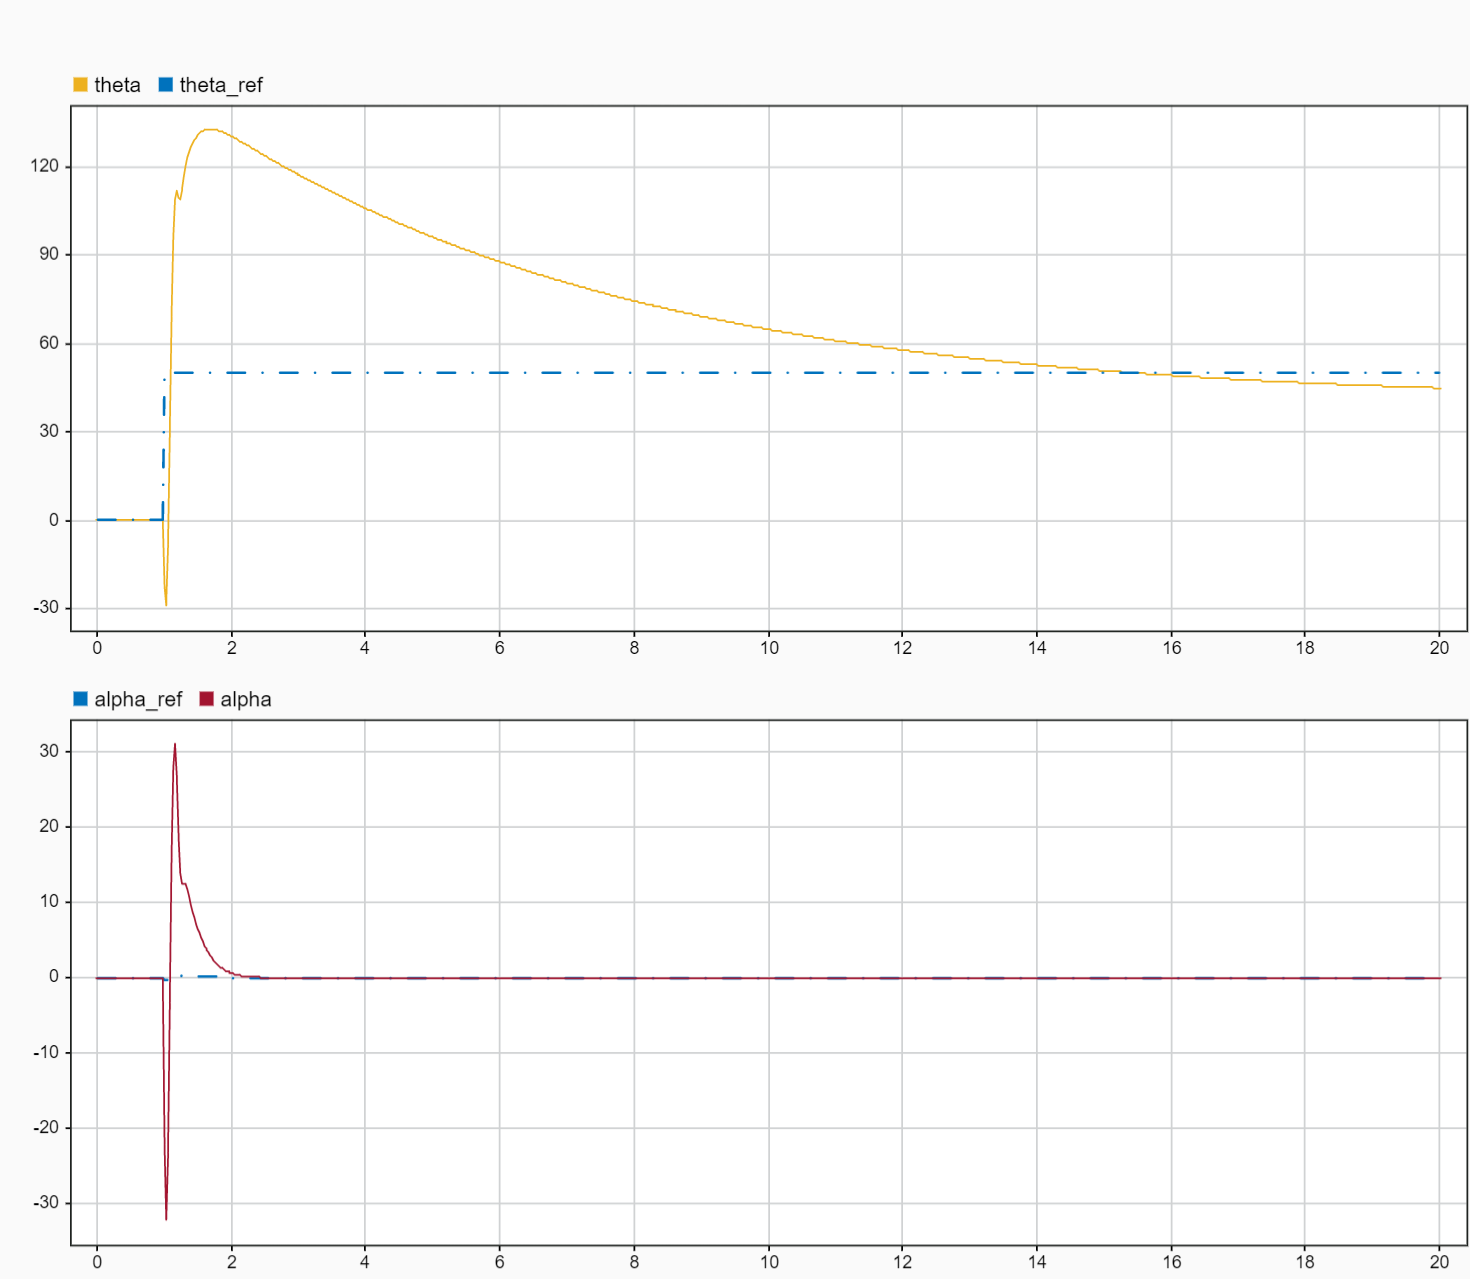

As we can see, the designed control loop can successfully control even the nonlinear model of the rotary inverted pendulum system. We can also notice that while successfull, the system input response differes from the linearized model. Mainly the stabilization of the rotary base on the $\theta_{ref}$ value is much slower for the nonlinear model. We should also note, that the nonlinear system used for this evaluation is still just a mathematical model, which inevitably differes from the reality Therefore, **we still cannot be sure if our controller design is capable of controlling the real physical device**. Unfortunately, the only way to definitely prove that cappability is to test the controller on the actual device. Since testing on a real device is typically problematic in practice, we can try to update our model to better account for the  real-world uncertainties. This is topic is covered by the **Robust Control Theory**.

### $\mathcal{H}_\infty$ Synthesized Dynamical Controller

When the controller is deployed in the real-world application, it inevitably faces a variety of input signals consisting of the command (reference) and the disturbance signals. While we might have some control over the command signals, we, most likely, cannot account for every possible disturbance. From the Frequency Analysis theory, we know that every input signal can be represented as a harmonic signal, and every system is bound to have a resonant frequency, which plays a crucial role in the ability of the controller to remain stable. **To account for the unpredictability of the operating environment**, $\mathcal{H}_\infty$** synthesis looks at the whole frequency response of our control loop**, and designs a controller which even at the worst-case scenario - resonant frequency - remains stable while enforcing a **performance boundary **$\gamma$. It uses **dynamic transfer functions (filters)** as weight functions $W_1(s)$, $W_2(s)$, and $W_3(s)$ to shape the controllers behaviour. The weight functions change their penalty depending on the frequency of the signal (punishing low-frequency errors but ignoring high-frequency ones). Because they are dynamic, they add extra states to the final controller turning it into a *Dynamical* Controller (PID is a dynamical controller as well). 

We first choose our weight functions:

**Sensitivity Function Weight **$W_1$**:**

$W_1(s)$ is typically assigned to the **tracking error** or **sensitivity function **( $S$ ). It dictates how well the system should track a reference or reject low-frequency disturbances.

**Typical Form:** Often modeled as a low-pass filter or an integrator-like function:


$$W_1(s) = \frac{\frac{s}{M} + \omega_B}{s + \omega_B A_{err}}$$


where $A_{err}$ is the maximum allowable steady-state error, $\omega_B$ is the desired bandwidth, and $M$ is the peak sensitivity target.

s = tf('s');

Int_filter = 1 / (s + 1e-2);

W1_alpha = makeweight(15, [30 1], 0.1);
W1_theta = makeweight(15, [30 1], 0.1) * Int_filter;

W1 = [W1_alpha,     0    ; 
         0    , W1_theta];

W1.StateName = {'Alpha', 'Theta', 'Filter'};
W1.InputName  = {'Alpha_Error', 'Theta_Error'};
W1.OutputName = {'Weighted_Alpha_Err', 'Weighted_Theta_Err'};
W1

W1 =
 
  A = 
            Alpha   Theta  Filter
   Alpha   -1.994       0       0
   Theta        0  -1.994       4
   Filter       0       0   -0.01
 
  B = 
           Alpha_Error  Theta_Error
   Alpha             4            0
   Theta             0            0
   Filter            0            1
 
  C = 
                  Alpha   Theta  Filter
   Weighted_Alp   7.429       0       0
   Weighted_The       0   7.429     0.1
 
  D = 
                 Alpha_Error  Theta_Error
   Weighted_Alp          0.1            0
   Weighted_The            0            0
 
Continuous-time state-space model.



**Control Sensitivity Function Weight **$W_2$**:**

$W_2(s)$ is assigned to the control input ( $u$ ) or the control sensitivity function ( $KS$ ). It penalizes excessive actuator usage.

Note: *Typically is not necessary for modeling purposes but Im including it anyway for demonstration - intentionally setting its parametrs negltable to not mess the design too much.*

W2 = makeweight(2, 0.5, 0.05);

W2.StateName = {'Actuator_Filter_State'};
W2.InputName  = {'Motor_Voltage'};
W2.OutputName = {'Weighted_Control_Effort'};
W2

W2 =
 
  A = 
                 Actuator_Fil
   Actuator_Fil       -0.2883
 
  B = 
                 Motor_Voltag
   Actuator_Fil             1
 
  C = 
                 Actuator_Fil
   Weighted_Con        0.5622
 
  D = 
                 Motor_Voltag
   Weighted_Con          0.05
 
Continuous-time state-space model.



**Complementary Sensitivity Function Weight **$W_3$**:**

$W_3(s)$ is assigned to the complementary sensitivity function ( $T$ ) and represents unmodeled dynamics or sensor noise.

W3_alpha = makeweight(0.5, [30 1], 20);
W3_theta = makeweight(0.5, [30 1], 20);

W3 = [W3_alpha,     0    ;
         0    , W3_theta];

W3.StateName = {'Alpha', 'Theta'};
W3.InputName  = {'Alpha_Output', 'Theta_Output'};
W3.OutputName = {'Weighted_Alpha_Out', 'Weighted_Theta_Out'};
W3

W3 =
 
  A = 
          Alpha  Theta
   Alpha   -692      0
   Theta      0   -692
 
  B = 
          Alpha_Output  Theta_Output
   Alpha           128             0
   Theta             0           128
 
  C = 
                  Alpha   Theta
   Weighted_Alp  -105.4       0
   Weighted_The       0  -105.4
 
  D = 
                 Alpha_Output  Theta_Output
   Weighted_Alp            20             0
   Weighted_The             0            20
 
Continuous-time state-space model.



Inspecting the weights, we can notice something strange: $W_1$ has 3 state variables and $W_2$ has only 2. The two state variables $x_1$ and $x_2$ corespond to the outputs of our plant ( $x_1 = \alpha$ and $x_2=\theta$). However, based on my empiric experience, it seems that the $H_\infty$ synthesis designs a controller that effectively cancels out the inherited integrator of the rotary base, and therefore the resulted closed loop suffer from steady state error. To compensate this, I have augmented the $W_1$ with an artificial filter, whith a stable pole very close to $\Re(p_{filter} \approx 0)$ (to keep the system proper). 

 Int_filter

Int_filter =
 
     1
  --------
  s + 0.01
 
Continuous-time transfer function.



This filter then manifests into its own state: $x_3$ (notice the $A_{x_3, x_3} =  -1^{-2}$ is the filter's pole). We can visualize the Weight Functions and their produced Design Envelopes

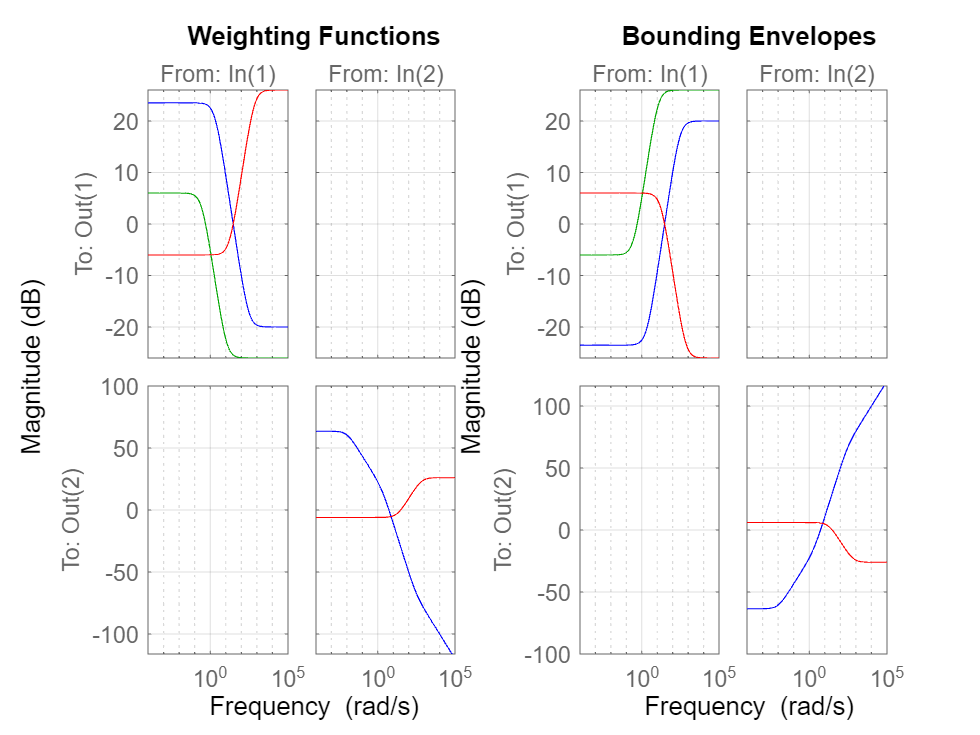

% Visualize the inverse of the weighting functions to see our desired bounds
figure;
subplot(1, 2, 1);
bodemag(W1, 'b', W2, 'g', W3, 'r');
% legend('W1', 'W2', 'W3', 'Location', 'best'); % Legend blocks view
title('Weighting Functions')
grid on;

subplot(1, 2, 2);
bodemag(1/W1, 'b', 1/W2, 'g', 1/W3, 'r');
% legend('1/W1', '1/W2', '1/W3', 'Location', 'best'); % Legend blocks view
title('Bounding Envelopes')
grid on;

Now, by combining the weight functions and the original rotary inverse pendulum linearized model we obtain the **generalized augmented Plant **$P$:

P_ss = augw(lin_system_ss, W1, W2, W3);
size(P_ss)

State-space model with 7 outputs, 3 inputs, and 10 states.


As we can see the augmented plant $P$ is a massive state space with about 10 state variables.

**Tuning the **$\mathcal{H}_\infty$** controller**

Now we can use the Matlab's *hinfsyn(P_ss) *to solve the optimization problem and design the dynamic controller for us:

[R_ss, sys_CL, gamma] = hinfsyn(P_ss);
size(R_ss)

State-space model with 1 outputs, 2 inputs, and 10 states.


The controller shares the plant's state dimensions but differes in inputs - the plant's measured outputs ( $\alpha$ and $\theta$ ) and the controller's actuator output ( $u$ ).

However, designing a controller that can satisfy all our expectations is rather difficult, and in some cases, mathematically impossible. To quantify the degree to which the controller fails to satisfy our expectations, we can use the worst-case gain ceiling - the $\mathcal{H}_\infty$** norm** (the $\gamma$**-gain upper bound** or the $\mathcal{H}_\infty$** performance bound**):


$$\|T_{zw}(s)\|_\infty < \gamma$$


where $T_{zw}$ is the closed-loop transfer matrix from the exogenous inputs $w$ to the regulated outputs $z$.

For the controller to have some safety margin even for the worst case scenario, the performance bound should be $0< \gamma < 1$.

For our design the performance boud was evaluated to:

fprintf('Gamma: %f\n', gamma);

Gamma: 18.962188


This means the controller, for the worst case scenario, reaches error of approximatelly 19% of the input signal. While this seems like a failure, it is rather acceptable performance for our usecase. 

Note: *Since this outcome is heavily affected by the weight choice, it was rather difficult keeping the performance bound under houndreds with reasonable performance. The lowest performance bound I was capable of reaching was around 5. But in those cases the steady state error was higher than 50% of *$u$*.*

*We can visualise our sensitivity functions:*

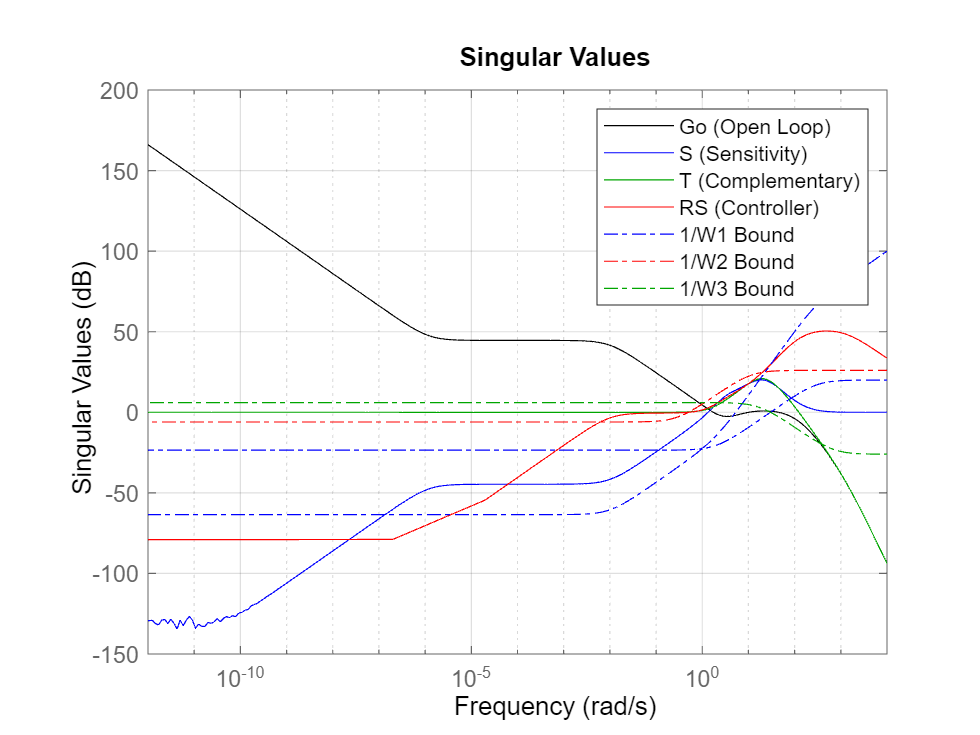

% Calculate the sensitivity functions
loops = loopsens(lin_system_ss, R_ss);

figure;
sigma(loops.Li, 'k', loops.Si, 'b', loops.Ti, 'g', R_ss, 'r', 1/W1, 'b-.', 1/W2, 'r-.', 1/W3, 'g-.')
legend('Go (Open Loop)', 'S (Sensitivity)', 'T (Complementary)', 'RS (Controller)', '1/W1 Bound', '1/W2 Bound', '1/W3 Bound')
grid on

$\mathcal{H}_\infty$ **Synthesised** **Controller Closed Loop Simulation (Linearized Model)**

% Closed Loop
SIMO_hinf_CL_ss = loops.To(:,2);

isstable(SIMO_hinf_CL_ss)

ans = logical
   1


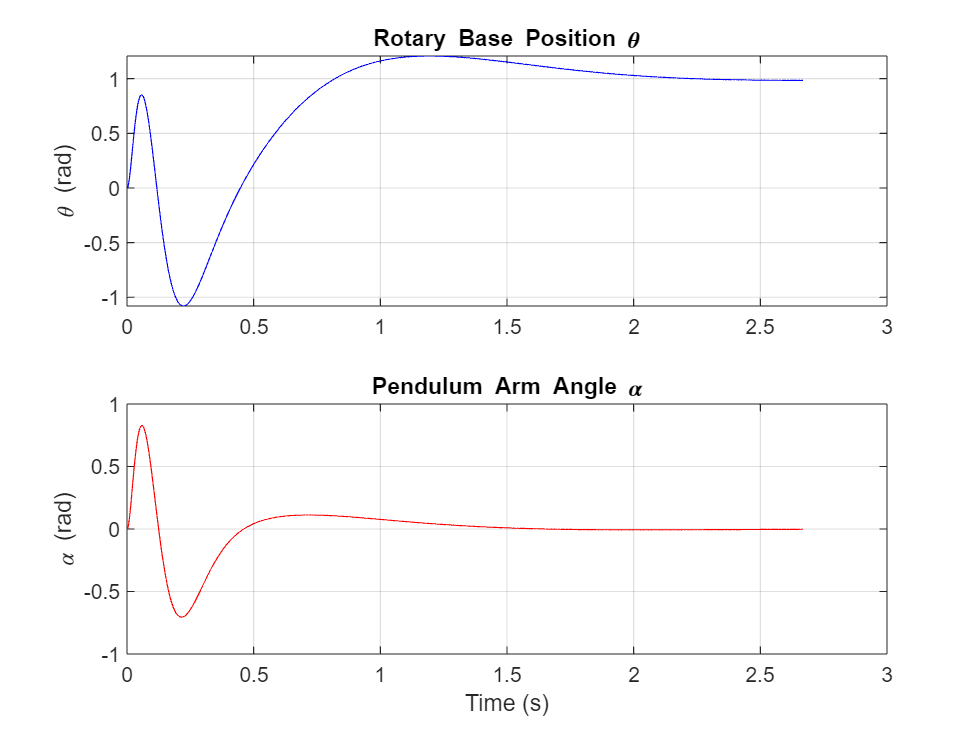


duration = NaN; % [s]
[y, t] = step(SIMO_hinf_CL_ss, duration);

figure('Name', 'H-inf Closed-Loop Step Response');
subplot(2, 1, 1);
% y(:, 2) extracts the 2nd output (Theta)
plot(t, y(:, 2), 'b');
title('Rotary Base Position \theta');
ylabel('\theta (rad)');
grid on;

subplot(2, 1, 2);
% y(:, 1) extracts the 1st output (Alpha)
plot(t, y(:, 1), 'r'); 
title('Pendulum Arm Angle \alpha');
xlabel('Time (s)');
ylabel('\alpha (rad)');
grid on;

step_info = stepinfo(SIMO_hinf_CL_ss);
tau_theta = step_info(2).SettlingTime

tau_theta = 2.0581

We can immediately notice that the performance of the controller designed by the $\mathcal{H}_\infty$ synthesis is way more pessimistic in comparison with previous controllers. Stabilizing the rotary base ( $\theta$ ) became approximately 2.6 times slower than the Cascade PID Control Loop.

The core difference now is that the $\mathcal{H}_\infty$ controller is mathematically guaranteed to not get destabilized, even for the worst-case input frequencies (resonances). For such cases, the controller will compromise and follow the reference or suppress disturbances with some error (**scaled by the achieved performance bound **$\gamma$). Conversely, the Cascade PID Control Loop and State Feedback controllers are not capable of such compromises; they will try to follow the reference perfectly - inherently risking hitting a resonant frequency and becoming completely unstable.

#### $\mu$ Synthesis

While $\mathcal{H}_\infty$ takes into account the unpredictable operating environment, it does not account for the imperfection of the model itself. To address the model uncertainties, we can expand the $\mathcal{H}_\infty$ synthesis with $\mathcal{\mu}$ synthesis. $\mathcal{\mu}$ Synthesis iteratively conducts $\mathcal{H}_\infty$ synthesis over the uncertain model parameters evaluating different parameter variations to choose the design that yields the best results.

By replacing some of the pendulum parameters - such as pendulum mass or motor constant - with uncertain values, we generalize the whole model into an uncertain state-space system.

% Define physical parameters with explicit uncertainity +/- bounds
uncertain_parameters.m_p = ureal('m_pend', 0.2, 'Percentage', 10); % Pendulum mass: 0.2 kg +/- 10%
uncertain_parameters.k_t = ureal('K_motor', 0.05, 'Percentage', 15);  % Motor constant: 0.05 N-m/V +/- 15%

% A custom function that allows us to obtain the linearized rotary inverted pendulum in the upright position for any model parameters. 
lin_system_uss = uss(lin_rotary_pendulum_model(uncertain_parameters));

lin_system_uss.StateName = {'alpha', 'alpha_dot', 'theta', 'theta_dot'};
lin_system_uss.InputName = {'V_m'};
lin_system_uss.OutputName = {'alpha', 'theta'};

Once again, we construct the generalised augment plant $P_{unc}$ using the uncertain state-space pendulum model and the weights functions from above.

% Build the Augmented Plant using your existing W1, W2, W3 weights
P_unc = augw(lin_system_uss, W1, W2, W3);

% Define the dimensions of the controller interface
n_meas = 2;  % Number of measurements passed to the controller (Alpha, Theta)
n_cont = 1;  % Number of control signals from the controller (V_m)

Then we run the Matlab's *musyn() *to obtain the optimized controller.

cacheFile = 'mu_synthesis_results.mat';

if isfile(cacheFile) && ~exist('K_mu', 'var')
    load(cacheFile);
else
    [K_mu, clperf] = musyn(P_unc, n_meas, n_cont);  % The mu synthesis took about 2 hours on my CPU
    save(cacheFile, 'K_mu', 'clperf');
end

% OR alternatively you can run the hardcoded custom function:
% K_mu = get_embedded_controller();

size(K_mu)

State-space model with 1 outputs, 2 inputs, and 180 states.


We can see that the generated controller became a massive dynamic system with 187 states. This is normal for $\mu$ synthesis, but it is still better to try to reduce the dimension with *balred(K).*

K_mu = minreal(balred(K_mu, 12));
size(K_mu)

State-space model with 1 outputs, 2 inputs, and 12 states.


$\mathcal{\mu}$ **Synthesised** **Controller Closed Loop Simulation (Linearized Model)**

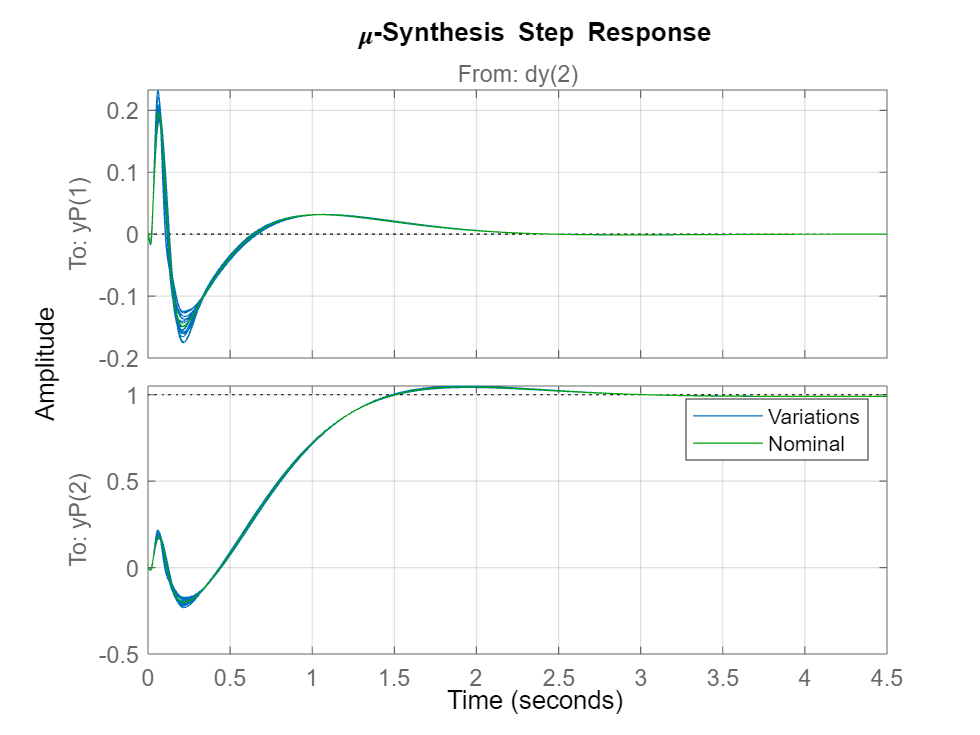

loops_mu = loopsens(lin_system_uss, K_mu);
SIMO_mu_CL_uss = loops_mu.To(:, 2);

duration = NaN;

figure;
h = stepplot(SIMO_mu_CL_uss, SIMO_mu_CL_uss.NominalValue,'g', duration);
grid on;
legend('Variations', 'Nominal');
title('\mu-Synthesis Step Response');

step_info = stepinfo(SIMO_mu_CL_uss.NominalValue);
tau_theta = step_info(2).SettlingTime

tau_theta = 2.5465

Here we can see that the $\mu$ synthesis did a really good job in designing a controller that - while slightly slower than the original $\mathcal{H}_\infty$ - withstands our model uncertainty variation.

Since both dynamic controllers - synthesized by $\mathcal{H}_\infty$ and PID are working with limited information about the system ( reduced output $\dim(Y) < \dim(X)$ ) the performance of the controller suffer. We can fully utilize our mathematical model and use the information about each state variable to significantly improve our controllers.

### **State Feedback Controller**

*State feedback controller* (or state regulator) in its pure form utilizes the principle of **full-state feedback**. It is essentially a proportional controller, which, however, unlike the classic proportional component of a P-controller, responds with a static gain to all state variables of the system and not just to its output.

The principle of state feedback consists in modifying the dynamics of the controlled system. In this way, it is possible to transform an unstable system into a stable one, provided that the controlled system is state-controllable. This property stems from the control action of the state feedback, which is directly proportional to the system's deviation from the stable position:


$$u = -K \cdot X$$


Due to the non-zero nature of the static gain coefficient $K$, it follows from the equation above that the stable position of the state feedback is at the point where all state variables are equal to zero: $X = 0$. This means that **feedback alone is not capable of tracking/controlling the system, but only of stabilizing it**. Therefore, for control purposes, it is necessary to augment the control action with information about the desired value at which the system should settle.

The state controller is then defined, as follows:


$$u = -K \cdot X + r$$


Where $r$ is the reference value, or in other words, the setpoint.

Since State Feedback controllers are essentially a proportional regulator acting on each state, they are also subjected to steady state error's. For that reason, Full-State Feedback Controllers are often extended with artificial integrators to compensate. However, our system is astatic - contains integrator ( $1/s$ ) inside of the rotary base - and therefore, it eliminates the steady state error on its own and we do not need to extend our controller this way.

**Simulink model of Full-State Feedback Control Loop**

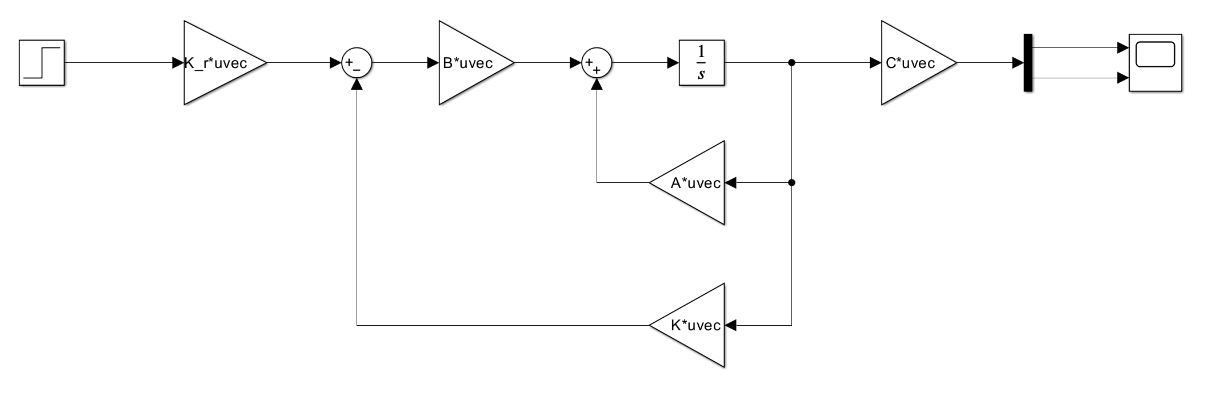

#### Full-State Feedback Controllability

A system is controllable if the rank $h$ of the controllability matrix $R$ is equal to the order $n$ of the controlled system.

The controllability matrix is defined as:


$$\mathbf{R} = \left[ \begin{array}{ccccc} \mathbf{B} & \mathbf{A} \cdot \mathbf{B} & \mathbf{A}^2 \cdot \mathbf{B} & \dots & \mathbf{A}^{n-1} \cdot \mathbf{B} \end{array} \right]$$


The rank of the controllability matrix $R$ is

system_order = size(A, 1); % Should be 4

% 1. Compute Controllability
R_mat = ctrb(A, B);
rank_R = rank(R_mat)

rank_R = 4

And therefore: 

if rank_R == system_order
    fprintf('SYSTEM IS FULLY CONTROLLABLE\n\n');
else
    fprintf('SYSTEM IS UNCONTROLLABLE\n\n');
end

SYSTEM IS FULLY CONTROLLABLE



To design the controller we need to calculate the appropriate gain matrix $K$. There are multiple ways to do this and therefore, I will dedicate a part of the work to some of the approaches.

#### Pole Placement

This is the simplest way to quickly setup a state controller. We simply pick and choose our desired poles and then adjust the gain of the $K$ matrix (using Matlab's *place()*) so that the poles of the extended dynamic matrix $A_{ext} = A - B \cdot K$ equal to our initial choice.

% Choose desired poles of the final system
desired_poles = [-1; -2; -3; -4]

desired_poles =     -1
    -2
    -3
    -4



% Calculate state gain matrix
K_placed = place(A, B, desired_poles)  % "place" does not allow for repeated poles (for example: p_1 = p_2)

K_placed =     3.8266    0.2821   -0.0149   -0.5874


% K = acker(A, B, desired_poles) % "acker" allows for repeated poles

% Compute the closed-loop system matrix
A_ext = A - B*K_placed; 
A_ext_poles = eig(A_ext)

A_ext_poles =    -4.0000
   -3.0000
   -2.0000
   -1.0000


As we can see, we were able to define a matrix $K$that successfully adjusts the systems overall dynamics in our desired way.

**Pole Placement Full-State Feedback Closed Loop Simulation (Linearized Model)**

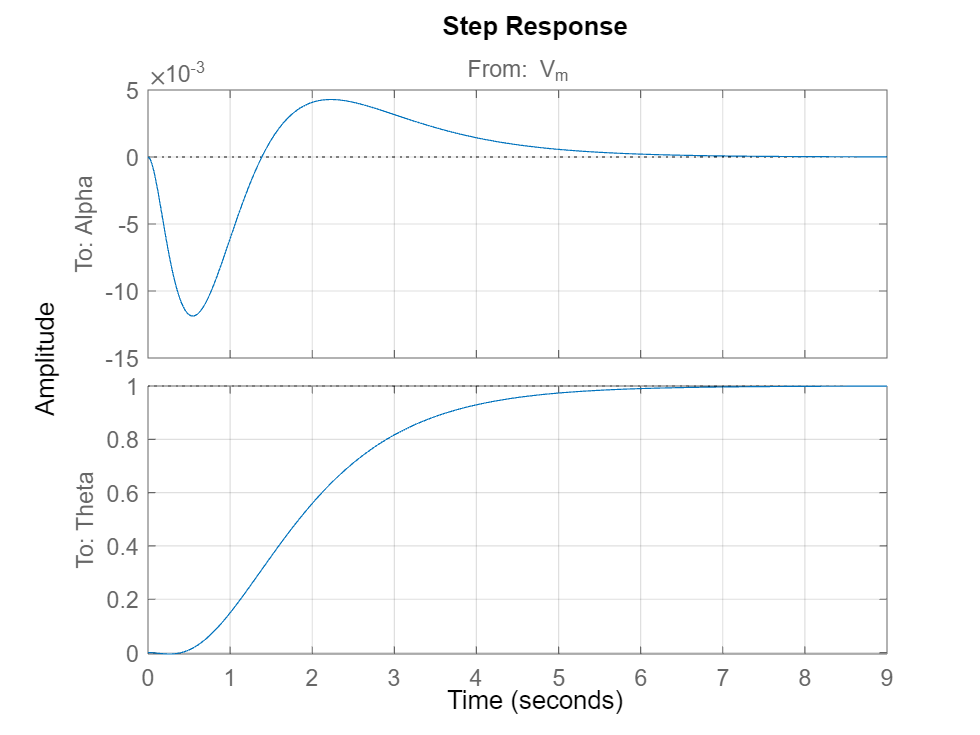

% Closed Loop
SIMO_fsfb_place_CL = ss(A_ext, B, C, D);

% Scale the reference gain K_r
K_dc = dcgain(SIMO_fsfb_place_CL);
K_r_place = 1 / K_dc(2);
SIMO_fsfb_place_CL.B = SIMO_fsfb_place_CL.B * K_r_place;

SIMO_fsfb_place_CL.StateName = {'Alpha', 'Alpha_dot', 'Theta', 'Theta_dot'};
SIMO_fsfb_place_CL.InputName = {'V_m'};
SIMO_fsfb_place_CL.OutputName = {'Alpha', 'Theta'};

figure; 
step(SIMO_fsfb_place_CL)
grid on;

step_info = stepinfo(SIMO_fsfb_place_CL(2,1));
tau_theta = step_info.SettlingTime

tau_theta = 5.2797

The final closed loop is also stable - the controller can successfully control the rotary base position ( $\theta$ ) without steady state error while keeping the pendulum arm $\alpha$ in the upright position. If we would compare this obtained input response with the input response obtained from the Cascade PID control loop, we would notice that this design is much slower. This points us towards one of the dissadvantage of the *Pole Placement * approach - The system dynamics are completely dictated by the poles that we have chosen (rather randomly) and therefore, to improve the system dynamics we have to choose better poles. Since the choice of the optimal poles manually is not exactly the most intuitive, other optimization strategies have been developed. 

#### **Linear Quadratic Regulator (LQR)**

With the LQR aproach, instead of guessing the optimal poles directly, we shift the choice towards performance choice. While still a choice, this time it is way more intuitive to set accordingly to the specific needs.

First we choose the **State Weighting Matrix**:

Q = diag([0.01; 0.01; 100; 0.01]);

the **Control Weighting Matrix**:

R_ss = 0.01

R_ss = 0.0100

and the **Cross-Coupling Weightning Matrix**:

N = [0; 0; 0; 0]

N =      0
     0
     0
     0


Then using Matlab's *lqr() we calculate the necessary gain matrix *$K$ that satisfies the optimalization problem.

K_lqr = lqr(lin_system_ss, Q, R_ss, N)

K_lqr =   267.6556   38.7241 -100.0000  -34.6918


% Compute the closed-loop system matrix
A_ext = A - B*K_lqr; 
A_ext_poles = eig(A_ext)

A_ext_poles =  -51.3097 +32.2788i
 -51.3097 -32.2788i
  -6.9635 + 0.0000i
  -6.3126 + 0.0000i


As we can see, we were able to define a matrix $K$that successfully adjusts the systems overall dynamics in our desired way.

**LQR Full-State Feedback Closed Loop Simulation (Linearized Model)**

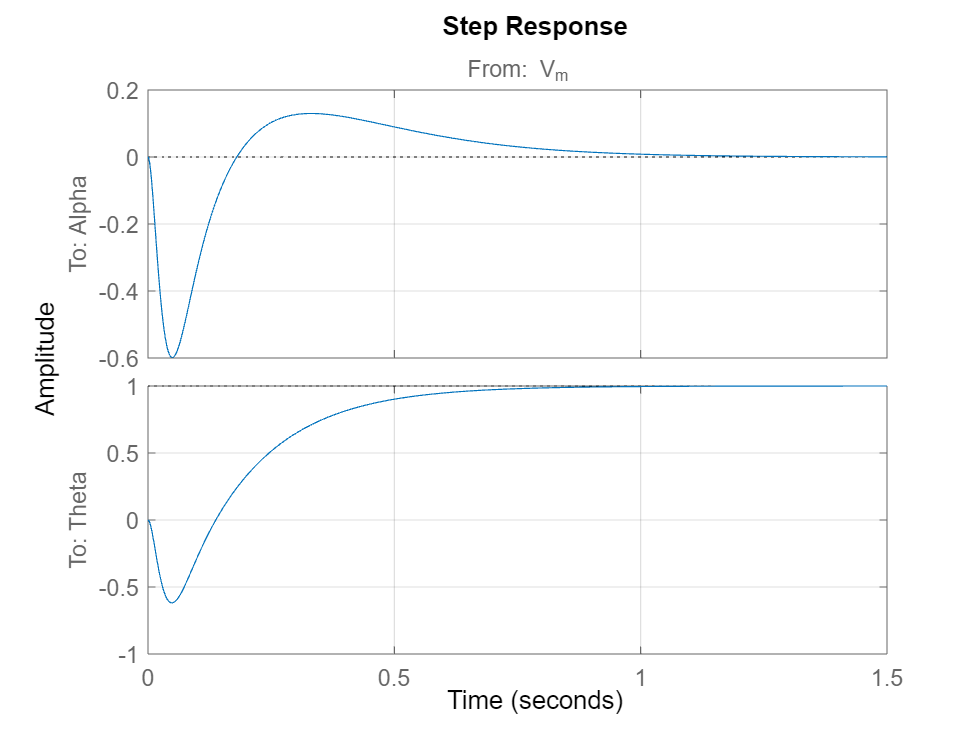

% Closed Loop
SIMO_fsfb_lqr_CL = ss(A_ext, B, C, D);

% Scale the reference gain K_r
K_dc = dcgain(SIMO_fsfb_lqr_CL);

% We command by inputing the theta reference so we should scale theta
K_r_lqr = 1 / K_dc(2);  

SIMO_fsfb_lqr_CL.B = SIMO_fsfb_lqr_CL.B * K_r_lqr;

SIMO_fsfb_lqr_CL.StateName = {'Alpha', 'Alpha_dot', 'Theta', 'Theta_dot'};
SIMO_fsfb_lqr_CL.InputName = {'V_m'};
SIMO_fsfb_lqr_CL.OutputName = {'Alpha', 'Theta'};

figure; 
step(SIMO_fsfb_lqr_CL)
grid on;

step_info = stepinfo(SIMO_fsfb_lqr_CL(2,1));
tau_theta = step_info.SettlingTime

tau_theta = 0.7502

Using LQR, we have once again successfully achieved stable control of the linearized model. This time, we were also able to beat the performance of the Cascaded PID Control Loop (tuned by *pidtune*), reducing the settling time of the rotary base by approximately $0.1\text{ s}$.

While iterative tweaking of the parameter settings for both control architectures might produce varying results, for strictly mathematical models, the full-state feedback controller is bound to have a superior performance ceiling over cascade PID control. This is because full-state feedback inherently possesses more degrees of freedom and utilizes complete information about the system's state variables simultaneously.

Since full-state feedback is mathematically superior and much easier to model, it is understandable to wonder why would we opt for cascade PID contrl loop to begin with. The answer comes down to real-world implementation. **Full-state feedback**, as the name suggest, **strictly requires the access to every (critical) state variable of the system**. This requirement is for real systems often times practically impossible to satisfy. Economically or physically, we can typically only access the *outputs* of the system, which represents a reduction of the true state-space. For example in our case, the output of the Quanser's rotary inverted pendulum platform is only a 2-dimensional vector $Y = \left[ \alpha ~ \theta \right]^T$ compared to the 4-dimensional state-space vector $X = [x_1 ~ x_2 ~ x_3 ~ x_4]^T$.

Fortunately, as shown in the following section of this work, there is a powerful workaround for implementing a full-state-feedback controller on systems that do not explicitly output all critical state variables: 

#### State Observer (State Estimation)

**Simulink model of Full-State Feedback Controller with Observer**

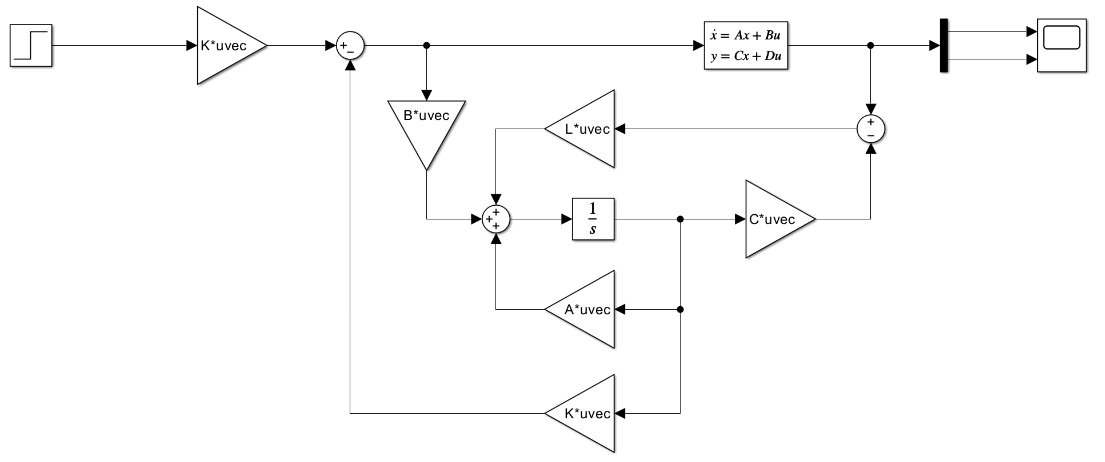

An observer uses the system's mathematical model to dynamically reconstruct the unmeasured state variables solely based on the measured outputs and control inputs.

A state observer represents a linearized model of the controlled system running in parallel with the actual physical plant. Based on its embedded knowledge of the system dynamics, the observer is capable of estimating the unmeasured state variables without the need to measure them directly. A state observer can only be implemented if the system is **observable**.

Observability is verified in a manner analogous to controllability, where the controllability matrix is replaced by the observability matrix in the following form:


$$\mathbf{P} = \left[ \begin{array}{c} \mathbf{C} \\ \mathbf{C} \cdot \mathbf{A} \\ \mathbf{C} \cdot \mathbf{A}^2 \\ \vdots \\ \mathbf{C} \cdot \mathbf{A}^{n-1} \end{array} \right]$$


The rank of the observabillity matrix $P$ is

P_mat = obsv(A, C);
rank_P = rank(P_mat)

rank_P = 4

And therefore:

if rank_P == system_order
    fprintf('SYSTEM IS FULLY OBSERVABLE\n\n');
else
    fprintf('SYSTEM IS UNOBSERVABLE\n\n');
end

SYSTEM IS FULLY OBSERVABLE



First we have to find the optimal observer gain matrix $L$. The observer's dynamics should be faster than the controller's full-state feedback loop ( $A_{ext}$ ).

% Define disturbance and measurement noise covariances
Gw = eye(4);       % Process noise enters all states
V  = [0.01 0;      % Sensor noise for Alpha
      0    0.01];  % Sensor noise for Theta

% Compute optimal observer gain L
L = lqe(A, Gw, C, Gw, V);

% Or we could use previously obtained poles of the state feedback and make
% them 5 times faster
% L = place(A', C', 5 * A_ext_poles)';

% Augmented system matrices
A_full = [A, -B*K_lqr;
          L*C, A - B*K_lqr - L*C];
      
B_full = [B; 
          B];
      
% We want to look at both the actual outputs and estimated outputs
C_full = [C, zeros(size(C));
          zeros(size(C)), C];
      
D_full = [D; D];

SIMO_fsfb_lqr_obsrv_CL = ss(A_full, B_full, C_full, D_full);

K_dc_obs = dcgain(SIMO_fsfb_lqr_obsrv_CL);
K_r_obs = 1 / K_dc_obs(2);
SIMO_fsfb_lqr_obsrv_CL.B = SIMO_fsfb_lqr_obsrv_CL.B * K_r_obs;

**LQR + Observer Full-State Feedback Closed Loop Simulation (Linearized Model)**

To demonstrate what the observer does, we can desynchronize the models by giving the system and the observer different set of initial conditions. This way the observer has to "catch-up" with the real system. This also demonstrates why the observer has to have faster dynamics then the obeserved system.

% Initial Condition Setup
x0_true = [0.1; 0; 0.2; 0]  

x0_true =     0.1000
         0
    0.2000
         0


x0_observer = [0; 0; 0; 0]  

x0_observer =      0
     0
     0
     0


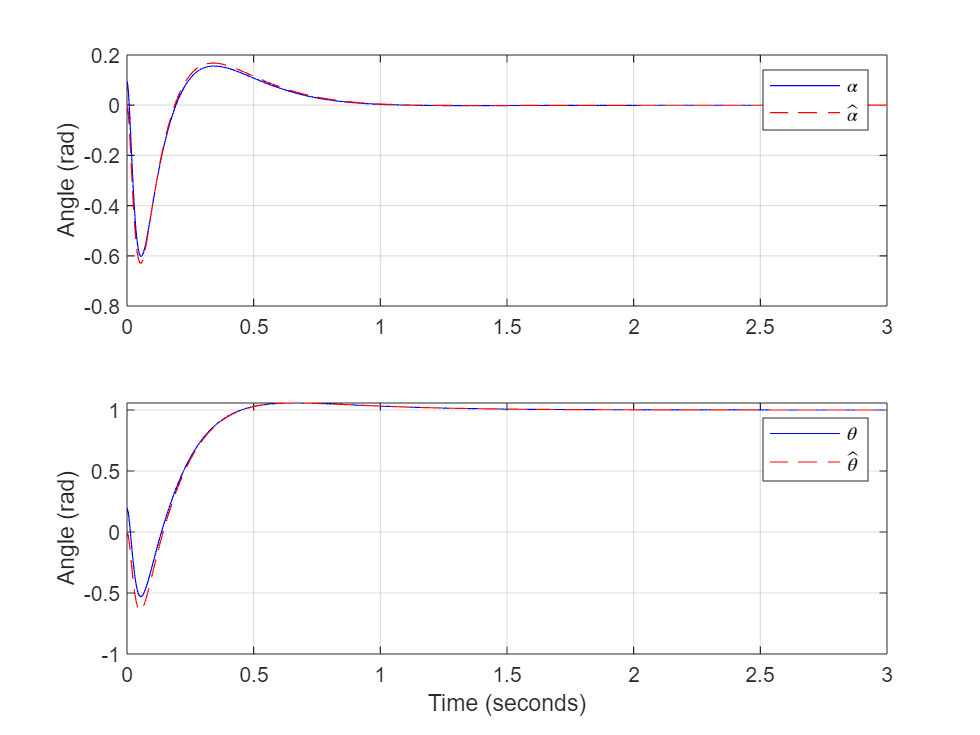

X0_augmented = [x0_true; x0_observer];

t_sim = 0:0.005:3;
u_step = 1 * ones(size(t_sim));
[y, t, x] = lsim(SIMO_fsfb_lqr_obsrv_CL, u_step, t_sim, X0_augmented);

figure;
title('LQR Control with State Observer Dynamics');
subplot(2,1,1);
plot(t, x(:,1), 'b-'); hold on;    % State 1: True Alpha
plot(t, x(:,5), 'r--');          % State 5: Estimated Alpha
grid on;
ylabel('Angle (rad)');
legend('$\alpha$','$\hat{\alpha}$', 'Interpreter', 'latex');

subplot(2,1,2);
plot(t, x(:,3), 'b-'); hold on;   % State 3: True Theta
plot(t, x(:,7), 'r--');         % State 7: Estimated Theta
grid on;
xlabel('Time (seconds)');
ylabel('Angle (rad)');
legend('$\theta$', '$\hat{\theta}$', 'Interpreter', 'latex');

The observer starts at 0 but gradually converges to follow the actual state (note the input signal is scaled by 0.01 to highlight the differences).

While this elegant approach bridges the data gap, it introduces two strict engineering constraints:

- **Observability:** Not every physical system is mathematically observable; if the hidden states do not structurally imprint onto the outputs, they cannot be recovered.

- **Model Dependency:** We must possess a highly accurate mathematical model of the controlled system.

Even when an analytical model is available, its real-world imperfections and unmodeled dynamics will inevitably introduce estimation errors into our control loop.

A PID controller, by contrast, is completely model-free; it can be tuned purely through empirical, experimental methods on the physical hardware. Furthermore, a cascade PID architecture offers distinct practical advantages that a standard full-state-feedback control loop does not inherently provide, such as seamless anti-windup implementation to mitigate actuator saturation, enhanced attenuation of unmodeled high-frequency dynamics, and straightforward fault isolation between the tracking loops.

For these reasons, despite their theoretical limitations, cascade PID control loops remain the industry benchmark for real-world engineering applications - particularly when controlling complex systems that are highly non-linear or exceptionally difficult to model.

### $\mathcal{H}_\infty}$ Synthesized Full-State Feedback Controller

While we could model dynamic controller for each state, the beauty of State Feedback Controller lies in the simplicity of the simple proportional feedback matrix $K$. This means that we can skip the complicated frequency response shaping and define the weighting functions as simple static matrixes. 

W_x = diag([10, 1, 100, 1])  % Penalize states (Alpha, Alpha_dot, Theta, Theta_dot)

W_x =     10     0     0     0
     0     1     0     0
     0     0   100     0
     0     0     0     1


W_u = 0.1                    % Penalize control effort (Voltage)

W_u = 0.1000

Since Matlab's *augw() requires the dynamic weights, we have to *construct the **Generalized Augmented Plant** $P$ manually.

B_w = B; % assuming process disturbance 'w' enters the system through the same channels as 'u'

[n, m] = size(B); % n = number of states, m = number of inputs

% Build the state space matrixes from the exogenous inputs w to the
% regulated outputs z
C_z = [W_x; zeros(m, n)];
D_z1 = zeros(n + m, size(B_w, 2)); % From disturbance w to z
D_z2 = [zeros(n, m); W_u];         % From control input u to z
C_y = eye(n);
D_y1 = zeros(n, size(B_w, 2));
D_y2 = zeros(n, m);

% Combine into the Augmented Plant matrix P
P_ss = ss(A, [B_w, B], [C_z; C_y], [D_z1, D_z2; D_y1, D_y2]);
size(P_ss)

State-space model with 9 outputs, 2 inputs, and 4 states.


$\mathcal{H}_\infty$ **Synthetised Gain Matrix **$K$**:**

[controller_ss, ~, gamma, info] = hinfsyn(P_ss, n, m);
% Extract the true static state-feedback matrix K_hinf
K_hinf = -info.KFI(1, 1:n)

K_hinf = 1.0e+04 *

    1.8663    0.2703   -0.7120   -0.2437


with the **performance bound **$\gamma$ 

gamma

gamma = 0.1010

Immediately we can notice much better performance bound $\gamma$. 

$H_\infty$ **Full-State Feedback Closed Loop Simulation (Linearized Model)**

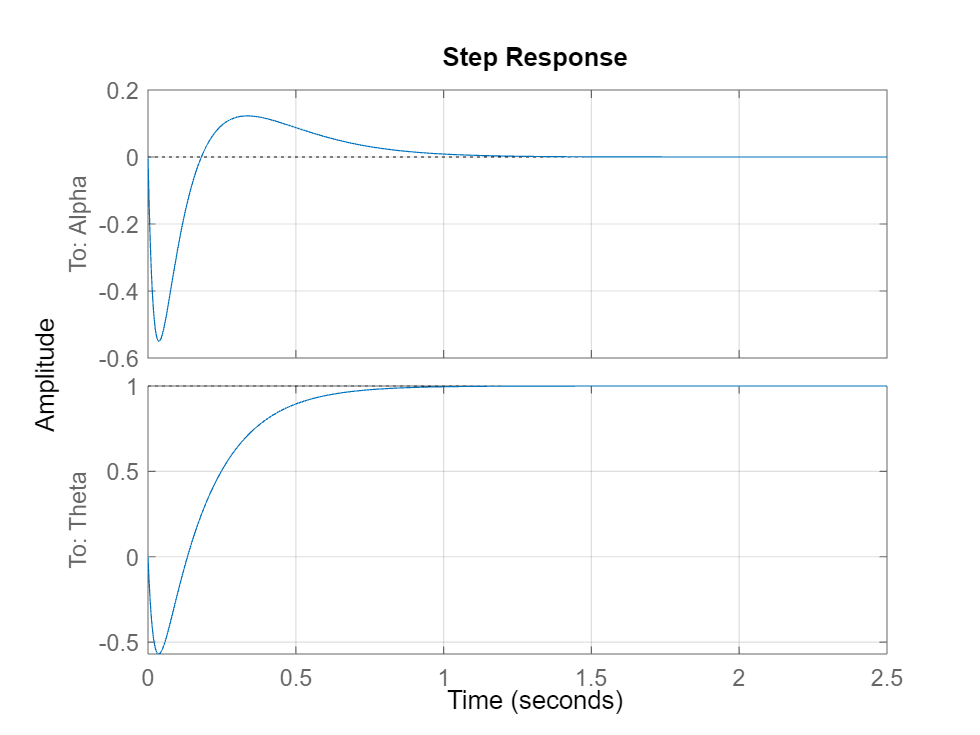

% Closed Loop
A_ext_hinf = A - B * K_hinf;
SIMO_fsfb_hinf_CL = ss(A_ext_hinf, B, C, D);

% Eliminate steady-state tracking error using your DC gain tracking method
K_dc = dcgain(SIMO_fsfb_hinf_CL);
K_r = 1 / K_dc(2); % Assuming Theta is your 2nd output channel
SIMO_fsfb_hinf_CL.B = SIMO_fsfb_hinf_CL.B * K_r;

% Set Labels
SIMO_fsfb_hinf_CL.StateName = {'Alpha', 'Alpha_dot', 'Theta', 'Theta_dot'};
SIMO_fsfb_hinf_CL.OutputName = {'Alpha', 'Theta'};

% Plot step performance
figure('Name', 'H-Infinity Control Performance');
step(SIMO_fsfb_hinf_CL);
grid on;

lin_info = stepinfo(SIMO_fsfb_hinf_CL(2,1));
tau_theta = lin_info.SettlingTime

tau_theta = 0.7642

Using the $\mathcal{H}_\infty$ approach, while achieving a slightly slower input response than the LQR approach, we were still able to surpass the performance of the Cascade PID Control Loop. Crucially, this design provides a mathematical guarantee that LQR cannot match: because the synthesis achieved an $\mathcal{H}_\infty$ performance index of $\gamma = 0.1010$, the closed-loop system acts as a highly effective frequency shield, guaranteeing the attenuation of worst-case external disturbances by roughly 90%.

## SIMULINK Simulation Setup

% Setting initial conditions
init_alpha = 0;       % degrees
init_alpha_dot = 0;   % degrees/s
init_theta = 0;       % degrees
init_theta_dot = 0;   % degrees/s

% State controller gain:
K = K_lqr;

X_0 = [init_alpha; init_alpha_dot; init_theta; init_theta_dot];

## Custom Functions

function [sys_ss] = lin_rotary_pendulum_model(params)
% getRotaryPendulumModel generates a linearized state-space model for a 
% rotary inverted pendulum in the upright position.
% This version preserves full parameter dependency structures for 
% Native Compatibility with Robust Control Toolbox ureal objects.

    %% 1. Define Default Parameters
    p.g = 9.83;          
    p.m_p = 0.127;       
    p.L_p = 0.337;       
    p.L_r = 0.216;       
    p.J_p = 0.0012;      
    p.J_r = 0.0020;      
    p.B_p = 0.0024;      
    p.B_r = 0.0024;      
    p.R_m = 2.6;         
    p.k_t = 7.68e-3;     
    p.k_m = 7.68e-3;     
    p.K_g = 70;          
    p.eta_m = 0.69;      
    p.eta_g = 0.90;      
    
    % Override defaults if custom parameters are provided (can be ureal)
    if nargin > 0 && isstruct(params)
        fields = fieldnames(params);
        for i = 1:length(fields)
            p.(fields{i}) = params.(fields{i});
        end
    end

    %% 2. Calculate Common Denominator (Sigma)
    sigma_core = 4*p.J_r*p.m_p*p.L_p^2 + 16*p.J_p*p.m_p*p.L_r^2 + 16*p.J_p*p.J_r;

    %% 3. Construct the A Matrix
    % Constructing rows explicitly forces MATLAB to dynamically compile 
    % an Uncertain Matrix (umat) if any parameters are ureal.
    row1 = [0, 1, 0, 0];
    
    row2 = [ ...
        (8*p.L_p*p.R_m*p.g*p.L_r^2*p.m_p^2 + 8*p.J_r*p.L_p*p.R_m*p.g*p.m_p) / (p.R_m * sigma_core), ...
        -(16*p.B_p*p.R_m*p.m_p*p.L_r^2 + 16*p.B_p*p.J_r*p.R_m) / (p.R_m * sigma_core), ...
        0, ...
        -(8*p.L_p*p.L_r*p.eta_g*p.eta_m*p.k_m*p.k_t*p.m_p*p.K_g^2 + 8*p.B_r*p.L_p*p.L_r*p.R_m*p.m_p) / (p.R_m * sigma_core) ...
    ];
    
    row3 = [0, 0, 0, 1];
    
    row4 = [ ...
        (4*p.L_p^2*p.L_r*p.g*p.m_p^2) / sigma_core, ...
        -(8*p.B_p*p.L_p*p.L_r*p.m_p) / sigma_core, ...
        0, ...
        -(2*(2*p.eta_g*p.eta_m*p.k_m*p.k_t*p.m_p*p.K_g^2*p.L_p^2 + 8*p.J_p*p.eta_g*p.eta_m*p.k_m*p.k_t*p.K_g^2 + 2*p.B_r*p.R_m*p.m_p*p.L_p^2 + 8*p.B_r*p.J_p*p.R_m)) / (p.R_m * sigma_core) ...
    ];

    A = [row1; row2; row3; row4];

    %% 4. Construct the B Matrix
    sigma_B = p.R_m * sigma_core;
    
    B = [ 0; ...
         (8*p.K_g*p.L_p*p.L_r*p.eta_g*p.eta_m*p.k_t*p.m_p) / sigma_B; ...
          0; ...
         (2*(2*p.K_g*p.eta_g*p.eta_m*p.k_t*p.m_p*p.L_p^2 + 8*p.J_p*p.K_g*p.eta_g*p.eta_m*p.k_t)) / sigma_B ];

    %% 5. Construct C and D Matrices
    C = [1 0 0 0; 
         0 0 1 0];
         
    D = [0; 
         0];

    %% 6. Construct Final LTI System
    sys_ss = ss(A, B, C, D);
    sys_ss.StateName  = {'Alpha', 'Alpha_dot', 'Theta', 'Theta_dot'};
    sys_ss.InputName  = {'V_m'};
    sys_ss.OutputName = {'Alpha', 'Theta'};
end

function K_mu = get_embedded_controller()
    % Hardcoded Mu Synthesized controller:
    A = [-1294.748361380391 -35.79643658859832 8.952612171349228 76.82665938588977 59.62986702831461 14.12004374921663 86.22868851731755 -411.6251000288179 -264.9880343837992 74.99485203794617 646.5256719213123 122.6326578570538;-363.4689187459019 -108.8664550834005 -1263.934302134894 -296.5543861539061 -173.2096324070342 28.09105480930155 -239.2401277004312 784.4778656889308 567.8556711416123 -166.4661659954542 -1265.568160668387 -203.0624796421237;-626.746239593723 -160.0569030996266 -400.2195101807076 -43.34116858336381 -94.08912364068286 7.165531907334914 -34.42708688526834 49.62580080294085 54.46991013882747 -15.82390941541049 -99.70080281871725 -2.902582480529629;-19.02956080122826 9.72944548305523 68.56244532074078 -24.38059298536256 -28.48259258442927 -0.1977623567597263 15.69117419697456 -33.21385502732387 -33.28332403362167 9.941285551051521 71.04614311888972 4.100705611446442;38.54034357501138 -6.233350771454567 95.63781400625247 -83.69329142559901 -649.4031188365072 -51.14479966504251 28.38589119488198 -42.66073661155603 -35.95867169897215 38.44893702900387 26.26079135355129 21.46674315295899;7.351819182387161 0.5165574020290207 -0.1730839345886097 -4.19179756704324 -43.44599904560219 -3.68254214038282 0.9474741771734768 2.546059171700388 1.843470290378904 2.453048832316409 -8.355204075945268 0.1163106267045172;-6.855559534625665 -3.742925138419965 -16.66490705024572 -13.82070457210573 62.15970352245737 7.68129158281046 -22.43891649464116 27.31402781550282 25.13508157544088 -36.71535175867377 -13.44885811058561 -11.50330653483571;-8.060106205489268 1.148576447274453 3.702275527356569 11.38784421914931 -38.15518957005288 -5.011748280957566 12.4089626608107 -20.22394972083419 -16.21271779957523 22.67292192042591 8.327285099383069 9.758985730400672;9.342388467550734 0.3158879597326724 -11.90058942701164 -21.36056861046968 95.06834364969285 11.49079716963786 -29.31686664274249 39.20024538211711 33.4441655792614 -49.83400395887809 -17.00037411005445 -17.87065822085018;54.97380590869582 -4.651362728277065 -88.12621046780986 -143.4240742526526 610.9985409880517 75.18553246734609 -199.1252123505305 267.4490697186549 230.389781988479 -339.2475079067787 -118.776993117124 -119.7705604896516;-6.043320639666768 0.1137173034579538 8.972237754929997 15.16252846414486 -65.02058828826704 -8.720542132384704 22.67871280118335 -28.79421359266601 -25.49423234160201 39.18241245232664 9.389476251296841 13.26193310155993;-3.52291537452568 0.2138092677614855 5.58574290329491 8.652676040611771 -41.05019709758272 -4.954430940612715 12.6431161009548 -16.73418923242258 -14.42810455805213 21.82477790647158 7.090470870702431 7.452384955256722];
    B = [3230.449821070645 -7.419604394083162;726.2029353848543 -4.030487214687632;1567.989851329674 -7.571801687584789;38.47075032690121 8.359067571270449;-240.7301546268057 3.120656650421961;-27.29244480820328 8.627839266399397;33.70484561706463 2.788816637516276;5.492245884869805 -1.715285910237227;0.5273678907622497 4.397133893235647;26.05923766050841 28.20226271312409;-1.603635395056388 -2.830147459442693;-1.917663836215222 -1.676292019706489];
    C = [38.59883586779409 -3.963958370149177 503.4676286197824 128.4697600088592 46.78848613764256 -12.76115947924846 103.8420695205782 -358.0106594231929 -254.391157702377 72.58356225818017 574.3286699718315 94.82273629255202];
    D = [-0.001336694674909931 0.001289087464103777];

    K_mu = ss(A, B, C, D);
end